# 1주차 — 개루프와 폐루프

**제어시스템설계** · 충남대학교 자율운항시스템공학과

**참고자료 — 먼저 볼 것**

아래 다섯 과목은 **이 강의의 담당교수가 직접 한 강의**입니다. 기초부터 대학원 과정까지 이어지므로 부족한 곳부터 보면 됩니다. 이 강의에서 쓰는 기호와 유도는 모두 그 안에서 자세히 다룹니다.

**MATLAB 이나 Simulink 가 아직 익숙하지 않다면** 실습에 들어가기 전에 아래를 먼저 하십시오. 무료이고 각각 몇 시간이면 끝납니다.

오늘 답할 질문은 하나입니다 — **피드백은 무엇을 해 주는가?**

결론부터

- 외란을 밀어낸다

- 모델이 틀려도 버틴다

- 두 효과의 크기가 똑같이 $\frac{1}{1+KG}$ 이다

문서 구성

- **1부** — 오늘 쓸 MATLAB 명령 아홉 개

- **2부** — 개루프와 폐루프 비교 (본론)

- **3부** — Simulink 로 확인

절 단위로 실행하십시오. 각 절에서 `Ctrl+Enter` 를 누르면 그 절만 실행됩니다.

## 0. 몸풀기 — 샤워기 온도 맞추기

샤워기 손잡이를 돌려 물 온도를 맞추는 두 가지 방법

- **방법 A** — 어제 좋았던 각도를 기억해 뒀다가 거기까지 돌리고 그대로 진입한다

- **방법 B** — 손을 대 보고, 차가우면 더 돌리고 뜨거우면 되돌린다

대응 관계

- 방법 A $=$ **개루프**

- 방법 B $=$ **폐루프**

방법 A 도 잘 됩니다. **조건이 어제와 같기만 하다면요.** 문제는 이때 생깁니다.

- 옆집에서 물을 쓰기 시작한다 → **외란**

- 보일러를 새로 바꿨다 → **모델이 바뀜**

오늘 배울 내용은 이 이야기가 전부이고, 나머지는 숫자로 확인하는 과정입니다.

## 0-1. 이미 해 본 적이 있습니다 — 운전

샤워기보다 더 익숙한 예가 있습니다. **운전**입니다. 강의자료 2장 4쪽에 나오는 그림을 블록으로 옮기면 이렇게 됩니다.

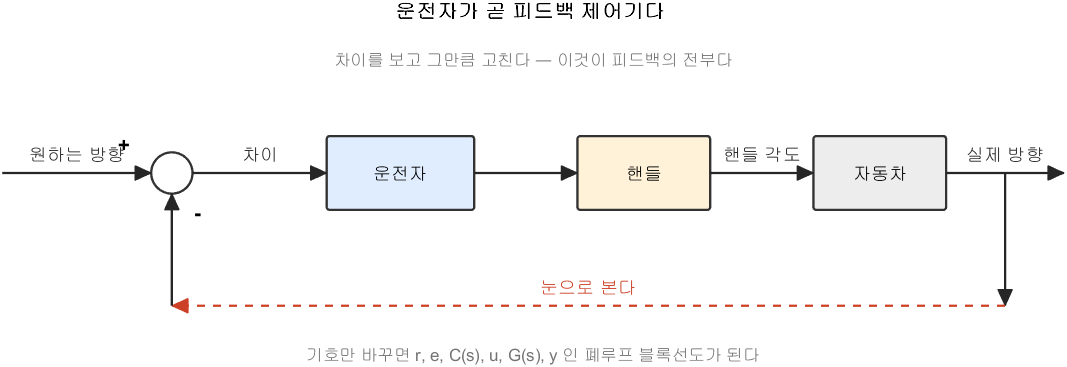

운전자가 곧 피드백 제어기다 (강의자료 2_Concept 4쪽)

**그림 파일** `car_feedback.png` — `common/dg_car.m` 의 `dg_car` · 다시 만들려면 `make_figures('car_feedback')`

**만드는 곳** — `common/dg_car.m` (`make_figures('car_feedback')`)

그림 해석 — **아래 회색 글씨가 이 그림의 요지입니다**

**이 그림의 빨간 점선 하나가 이 과목의 전부입니다.** 눈을 감고 운전하는 것이 개루프, 보면서 고치는 것이 폐루프입니다.

이 그림이 오늘 배울 블록선도와 **완전히 같은 것**입니다. 이름만 다릅니다.

그래서 이런 질문들이 그대로 옮겨집니다.

- **눈을 감고 운전하면?** $\rightarrow$ 개루프. 곧은 길에서는 잠깐 되지만 바람이 불면 벗어난다

- **옆바람이 분다면?** $\rightarrow$ 외란. 6절에서 다룬다

- **차가 바뀌어 핸들이 더 무겁다면?** $\rightarrow$ 모델 오차. 7절에서 다룬다

- **핸들을 너무 급하게 꺾으면?** $\rightarrow$ 이득이 너무 큼. 4절에서 다룬다

오늘 나오는 모든 그래프는 이 네 질문 중 하나에 대한 답입니다.

if isempty(which('plant_msd'))   % 경로가 아직 등록 안 되었으면 알아서 잡는다
    p_ = pwd;
    if ~isempty(mfilename('fullpath')), p_ = fileparts(mfilename('fullpath')); end
    for k_ = 1:4
        if isfile(fullfile(p_,'setup_path.m')), run(fullfile(p_,'setup_path.m')); break; end
        p_ = fileparts(p_);
    end
    clear p_ k_
end
clc; close all;

## 0-2. 오늘 돌려 볼 파일

강의노트를 읽다가 **직접 값을 바꿔 보고 싶을 때** 여는 파일들입니다. 모두 `W01_OpenClosedLoop` 폴더 안에 있습니다.

실행하는 법 — 파일을 열고 절 안에서 `Ctrl+Enter` 를 누르면 그 절만 돕니다. 전체는 `F5` 입니다. 처음 한 번은 `setup_path` 를 먼저 실행하십시오.

이 강의노트의 **그림은 전부** `make_figures.m` 이 만들어 `common/figures/` 에 넣어 둔 것입니다. 그림마다 어느 함수가 만들었는지 아래에 적어 두었습니다.

## 0-3. 오늘 한 장 요약

오늘 배우는 것은 **그림 두 장의 차이**입니다.

- **개루프** — 출력을 보지 않고 미리 계산해서 넣는다

- **폐루프** — 출력을 보고 틀린 만큼 고친다

오늘의 계단

- **1부** 오늘 쓸 MATLAB 명령 아홉 개 (`tf` 부터 `sim` 까지)

- **2부** 개루프와 폐루프를 나란히 놓고 비교

- **3부** Simulink 로 같은 것을 블록선도로 확인

결론부터 말하면 이렇습니다.

- 외란도 없고 모델도 정확하면 **개루프가 이깁니다** (더 간단하니까)

- 그런데 현실에는 둘 다 있습니다. 그래서 폐루프를 씁니다

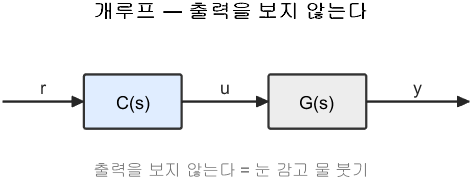

개루프 — 출력을 보지 않는다

**그림 파일** `loop_open.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_open')`

**만드는 곳** — `common/dg_loop.m` 을 `dg_loop('open', ...)` 로 부릅니다 **그림 해석** — 바로 다음 절에서 폐루프와 **나란히 놓고** 읽습니다. 두 그림의 차이가 오늘의 전부이므로 따로 읽지 않고 함께 봅니다.

## 0-4. 폐루프는 이렇게 생겼습니다

딱 하나 다릅니다. **출력을 다시 앞으로 가져와 뺍니다.** 그 뺀 값이 오차 $e$ 이고, 제어기는 그 오차를 보고 일합니다.

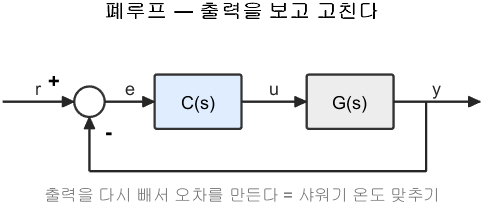

폐루프 — 출력을 보고 고친다

**그림 파일** `loop_closed.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_closed')`

**만드는 곳** — `common/dg_loop.m` 을 `dg_loop('open', ...)` 과 `dg_loop('closed', ...)` 로 부릅니다 **직접 확인해 보려면** — `W01_01_open_vs_closed.m` 이 두 구조를 코드로 만들고 응답을 나란히 그립니다

그림 해석 — **두 그림의 차이는 선 하나뿐입니다**

부품이 같은데 연결만 바꿨더니 성질이 완전히 달라집니다. 그 차이가 무엇인지 오늘 하루 종일 봅니다.

## 1부 — 오늘 쓸 MATLAB 명령

- 제어공학에서 쓰는 명령은 생각보다 적다

- 오늘 배울 아홉 개면 1~5주차 계산의 대부분을 할 수 있다

명령마다 세 가지를 확인합니다.

- **원리** — 무엇을 계산하는가

- **입출력** — 무엇을 넣으면 무엇이 나오는가

- **주의** — 흔히 하는 실수

## 1-1. `s = tf('s')` — 전달함수를 쓸 준비

- **하는 일** — 분자가 $s$, 분모가 $1$ 인 전달함수를 만들어 변수 `s` 에 담는다

- **입력** — 문자 `'s'` 하나

- **출력** — 전달함수 객체

왜 이렇게 하는가

- 이렇게 해 두면 그 뒤부터 `s` 를 보통 변수처럼 쓸 수 있다

- $\frac{1}{s+1}$ 을 `1/(s+1)` 이라고 쓰면 MATLAB 이 알아서 전달함수 나눗셈을 한다

- 종이에 쓴 식을 그대로 옮길 수 있어 **실수가 적다**

주의

- 이 줄을 빼먹고 `s` 를 쓰면 "정의되지 않았다"는 오류가 난다

- 그래서 이 과목의 모든 스크립트는 맨 위에 이 줄을 넣는다

s = tf('s')


s =
 
  s
 
연속시간 전달 함수입니다.
모델 속성


## 1-2. `tf` — 전달함수 만들기

전달함수는 초기조건이 모두 $0$ 일 때의 출력 대 입력 비입니다. **(주파수 영역에서)**


$$G(s) = \frac{Y(s)}{U(s)}$$


만드는 방법 두 가지

- **계수로** — `tf(분자계수, 분모계수)`. $s$ 의 높은 차수부터 나열

- **식으로** — `s` 연산자를 써서 수식 그대로. **이 과목의 기본 방식**

계수 벡터 쓰는 법

- $s^2+3s+2$ → `[1 3 2]`

- 빠진 차수는 $0$ 을 넣어야 한다. $s^2+2$ → `[1 0 2]`

두 방법은 완전히 같은 것을 만듭니다.

G_method1 = tf([1], [1 3 2])


G_method1 =
 
        1
  -------------
  s^2 + 3 s + 2
 
연속시간 전달 함수입니다.
모델 속성


G_method2 = 1/(s^2 + 3*s + 2)


G_method2 =
 
        1
  -------------
  s^2 + 3 s + 2
 
연속시간 전달 함수입니다.
모델 속성


## 1-2-1. 전달함수 안에는 무엇이 들어 있나

- 화면에는 분수 모양으로 나오지만 실제로는 **계수를 담은 자료구조**다

- `tfdata(G, 'v')` — 분자와 분모 계수를 벡터로 꺼냄

- 뒤의 `'v'` 는 "벡터로 달라"는 뜻. 빼면 셀 배열로 나와 다루기 번거롭다

[num, den] = tfdata(G_method2, 'v');
disp('분자 계수:'); disp(num)

분자 계수:
     0     0     1



disp('분모 계수:'); disp(den)

분모 계수:
     1     3     2



## 1-3. `pole` 과 `damp` — 시스템의 성격 읽기

- **극점(pole)** — 분모를 $0$ 으로 만드는 $s$. 달리 말하면 **전달함수를 "무한대로" 만드는 **$s$ 입니다

- 그 지점에서 $G(s)$ 가 무한대가 되므로 "극"이라는 이름이 붙었다

왜 중요한가

- 응답 안에 $e^{pt}$ 항이 나타나기 때문

- 극점 $p$ 하나가 **모드** 하나를 만든다

- 그래서 극점 위치만 보면 응답 모양을 짐작할 수 있다

극점 위치 읽는 법

- 실수부가 음수 → $e^{pt}$ 가 줄어듦 → **안정**

- 실수부가 양수 → $e^{pt}$ 가 커짐 → **불안정**

- 허수부가 있으면 → **진동**

두 명령의 차이

- `pole(G)` — 극점만 열벡터로 돌려줌 (복소수일 수 있음)

- `damp(G)` — 극점 · 감쇠비 (damping ratio) $\zeta$ · 고유진동수 (natural frequency) $\omega_n$ · 시정수 (time constant) 를 표로

G_ex = 1/(s^2 + 0.4*s + 4);
disp('극점:'); disp(pole(G_ex))

극점:
  -0.2000 + 1.9900i
  -0.2000 - 1.9900i



극점이 **실수 두 개**인 경우도 봅니다. 위의 복소수 극점과 비교해 보십시오. 실수 극점만 있으면 감쇠비가 $1$ 이상이고 진동하지 않습니다.

G_ex2 = 12/((s+3)*(s+4))


G_ex2 =
 
        12
  --------------
  s^2 + 7 s + 12
 
연속시간 전달 함수입니다.
모델 속성


disp(pole(G_ex2))

    -4
    -3



damp(G_ex2)

                                                       
    극점           감쇠             주파수            시정수     
                           (rad/seconds)    (seconds)  
                                                       
 -3.00e+00     1.00e+00       3.00e+00       3.33e-01  
 -4.00e+00     1.00e+00       4.00e+00       2.50e-01  


## 1-3-1. 극점 위치와 응답의 대응 — 세 가지 경우

위의 읽는 법을 세 가지 시스템으로 한 번에 확인합니다. **극점만 보고 응답을 맞혀 보십시오.**

G_1 = 1/((s+3)*(s+4));
G_2 = 1/((s+3i)*(s-3i));
G_3 = 1/((s-4)*(s-5));
disp('G_1 극점:'); disp(pole(G_1));

G_1 극점:
    -4
    -3



disp('G_2 극점:'); disp(pole(G_2));

G_2 극점:
   0.0000 + 3.0000i
   0.0000 - 3.0000i



disp('G_3 극점:'); disp(pole(G_3));

G_3 극점:
    5.0000
    4.0000



정말 그런지 응답으로 확인합니다. $G_3$ 는 발산하므로 세로축을 로그로 두지 않으면 나머지 둘이 안 보입니다.

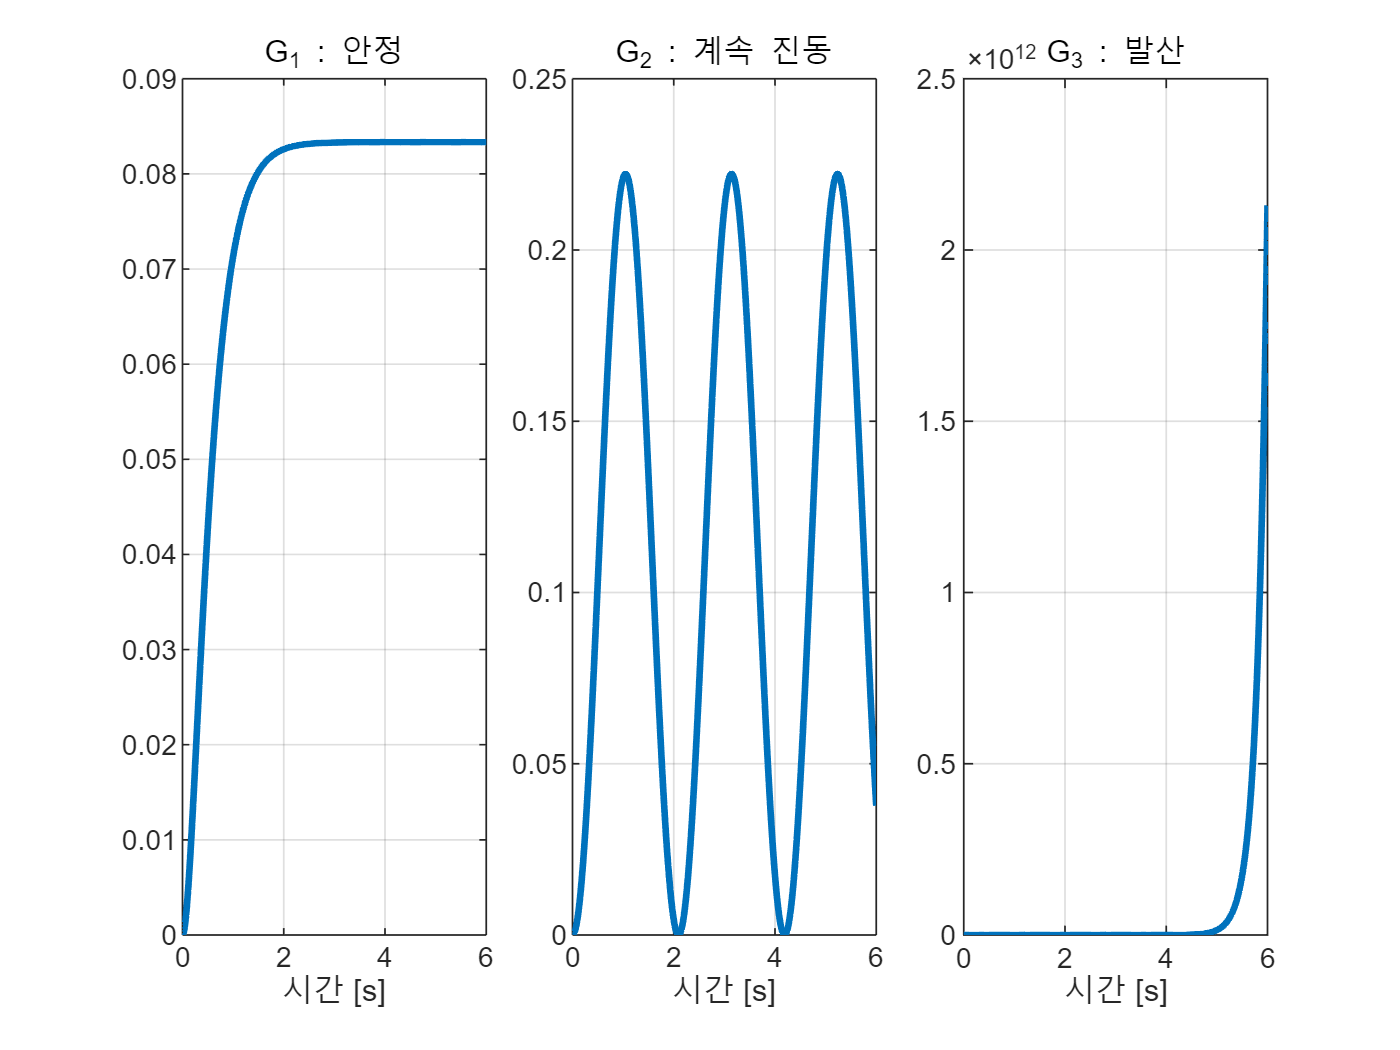

t_pz = 0:0.01:6;
tiledlayout(1,3,'TileSpacing','compact');
nexttile; plot(t_pz, step(G_1, t_pz), 'LineWidth', 2); grid on
title('G_1 : 안정'); xlabel('시간 [s]');
nexttile; plot(t_pz, step(G_2, t_pz), 'LineWidth', 2); grid on
title('G_2 : 계속 진동'); xlabel('시간 [s]');
nexttile; plot(t_pz, step(G_3, t_pz), 'LineWidth', 2); grid on
title('G_3 : 발산'); xlabel('시간 [s]');

## 1-4. `step` — 계단응답

- **계단입력** — $t=0$ 에 갑자기 $1$ 이 되어 그대로 유지되는 입력

- 스위치를 탁 켜는 것과 같다

왜 하필 계단인가

- 만들기 쉽다

- 빠르기와 진동 정도가 한눈에 드러난다

원리

- 전달함수를 내부적으로 상태공간으로 바꾼 뒤 미분방정식을 수치적분한다

- 손으로 라플라스 역변환을 하는 것과 결과는 같고 훨씬 빠르다

쓰는 방법이 둘인데 **이 차이를 꼭 알아 두십시오**

- `step(G)` — 출력을 안 받으면 **그림을 그려 줌**

- `y = step(G, t)` — 출력을 받으면 **그림 없이 숫자만** 돌려줌

입출력

- **입력** — `G` 는 전달함수, `t` 는 시간 벡터. `t` 를 생략하면 알아서 잡는다

- **출력** — 각 시각의 출력값 벡터. `t` 와 길이가 같다

- 이 과목에서는 두 번째를 주로 쓴다. 겹쳐 그리려면 데이터가 필요하기 때문

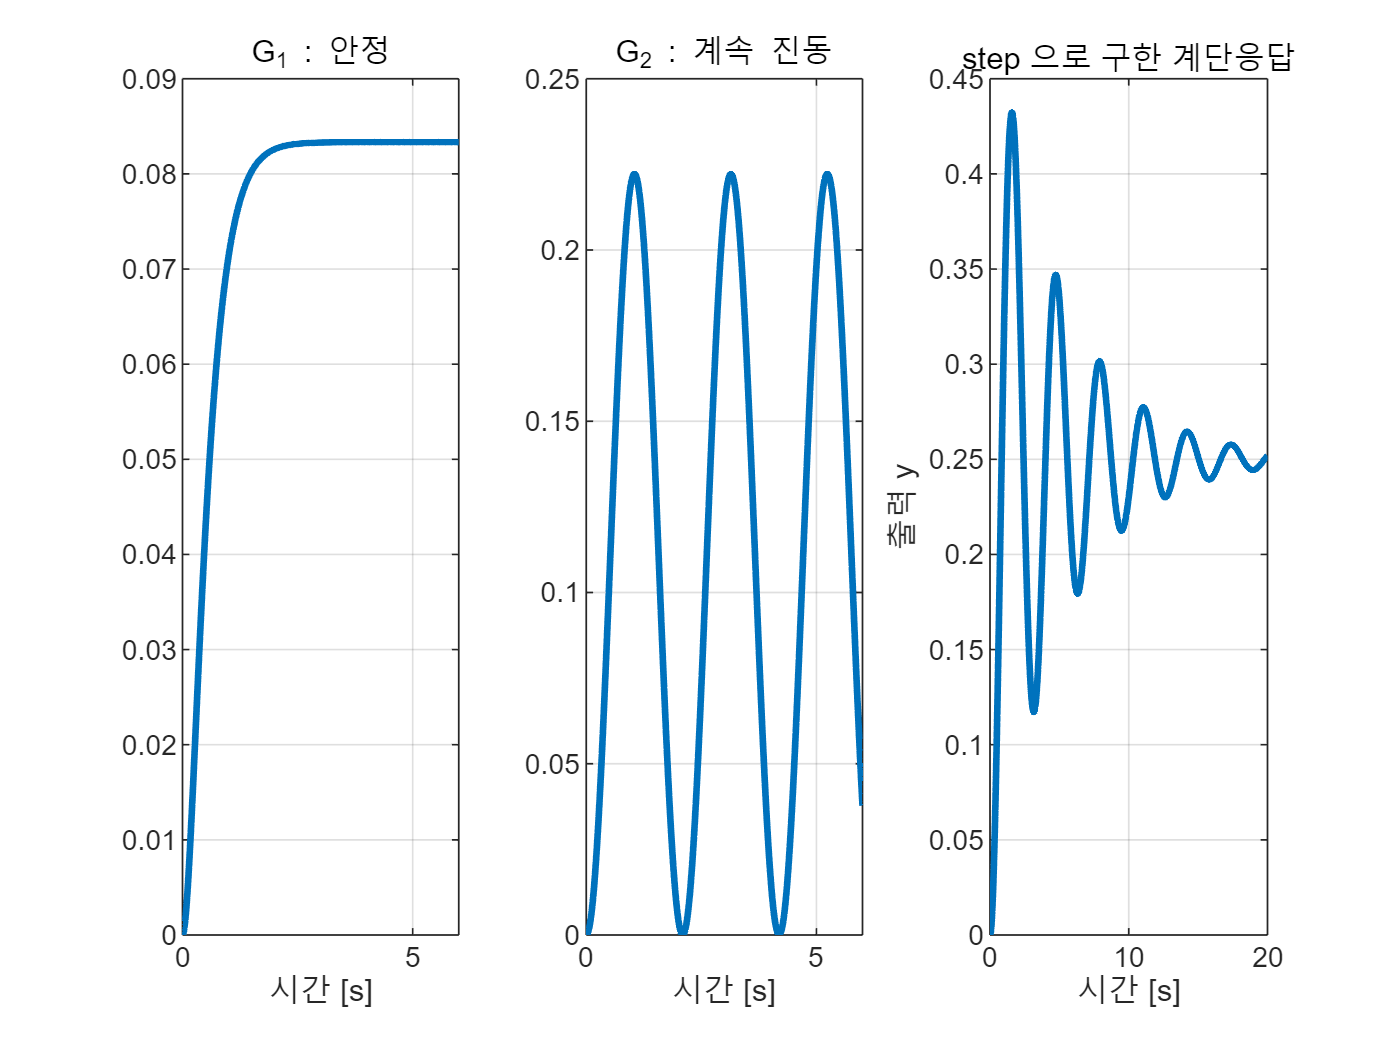

t = 0:0.01:20;
y = step(G_ex, t);
plot(t, y, 'LineWidth', 2); grid on
xlabel('시간 [s]'); ylabel('출력 y')
title('step 으로 구한 계단응답')

## 1-4-1. 계단 크기가 1 이 아니라면

- `step` 은 항상 크기 $1$ 인 계단을 넣는다

- 크기 $5$ 를 넣고 싶으면 **결과에 **$5$** 를 곱하면 된다**

- 입력이 $5$ 배면 출력도 $5$ 배라는 것이 바로 **선형**의 정의

아래 두 줄은 같은 결과를 줍니다.

- `y = 5 * step(G, t)`

- `y = step(5*G, t)`

y1 = 5 * step(G_ex, t);
y2 = step(5*G_ex, t);
fprintf('두 방법의 최대 차이: %.2e (같습니다)\n', max(abs(y1-y2)));

두 방법의 최대 차이: 0.00e+00 (같습니다)


## 1-5. `dcgain` — 천천히 넣으면 몇 배로 나오나

- **하는 일** — 전달함수에 $s=0$ 을 대입한다. 그게 전부다

- **입력** — 전달함수

- **출력** — 숫자 하나

그런데 왜 의미가 있는가

- 라플라스 변환에서 $s$ 는 "얼마나 빨리 변하는가"를 나타낸다

- 따라서 $s=0$ 은 "전혀 변하지 않는다", 즉 아주 천천히 넣는 경우


$$y_{ss} = G(0)\,u$$


- 계단입력을 넣고 충분히 기다리면 도달하는 값이 바로 $G(0)$

- 이것을 **최종값 정리**라 한다

어디에 쓰나

- 정상상태 오차 계산

- 목표가 $1$ 인데 $G(0)=0.8$ 이면 $20\%$ 모자란다는 뜻

y_long = step(G_ex, 0:0.01:200);
fprintf('dcgain(G)          = %.4f\n', dcgain(G_ex));

dcgain(G)          = 0.2500


fprintf('t = 20 s 에서의 값   = %.4f   (아직 진동이 남아 조금 어긋남)\n', y(end));

t = 20 s 에서의 값   = 0.2519   (아직 진동이 남아 조금 어긋남)


fprintf('t = 200 s 에서의 값  = %.4f   (충분히 기다리니 딱 맞음)\n', y_long(end));

t = 200 s 에서의 값  = 0.2500   (충분히 기다리니 딱 맞음)


## 1-6. `feedback` — 되먹임 루프 닫기

**오늘 가장 중요한 명령입니다.** 이 명령이 계산해 주는 것이 아래 그림입니다.

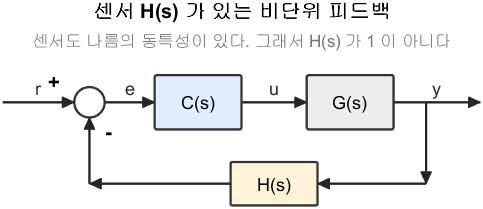

센서 H(s) 가 있는 비단위 피드백

**그림 파일** `loop_sensor.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_sensor')`

**만드는 곳** — `common/dg_loop.m` 을 `dg_loop('sensor', ...)` 로 부릅니다 **직접 확인해 보려면** — `W01_01_open_vs_closed.m` 에서 `feedback(G, H)` 를 `H` 를 바꿔 가며 불러 보십시오

그림 해석

이 그림에서 **한 바퀴 도는 길**이 $GH$ 입니다. 그래서 폐루프가 $G/(1+GH)$ 가 됩니다. 분모의 $GH$ 를 눈으로 확인해 두십시오.

## 1-6-0. 저 그림에서 출력이 어떻게 나오는가 — 한 줄씩

그림만 보고 답을 외우면 $H$ 가 붙는 순간 막힙니다. **신호를 따라가며 식을 세 줄 적으면** 끝납니다.

위 그림에서 화살표를 따라가며 만나는 순서대로 적습니다.

**1 단계의 **$Hy$** 를 잘 보십시오.** 원으로 들어오는 것은 $y$ 가 아니라 $Hy$ 입니다. 센서가 $H$ 배로 재서 보내 주기 때문입니다.

이제 3 번 식에 2 번을, 다시 1 번을 차례로 넣습니다.


$$y = G u = G\,C e = G C\,(r - H y)$$


괄호를 풀면


$$y = C G\,r - C G H\,y$$


$y$** 가 양변에 나왔습니다.** 왼쪽으로 모읍니다.


$$y + C G H\,y = C G\,r \qquad\Rightarrow\qquad (1 + CGH)\,y = C G\,r$$


양변을 $(1+CGH)$ 로 나누면 끝입니다.


$$\frac{y}{r} = \frac{CG}{1 + CGH}$$


**여기서 위와 아래가 무엇인지 구분해 두십시오.** 이것이 이 절의 요점입니다.

두 길이 지나는 상자가 다릅니다. 전방경로는 $H$ 를 안 지나고, 루프이득은 $H$ 까지 지납니다. $H=1$** 일 때만 둘이 같아집니다.**

제어기를 따로 두지 않고 $G$ 하나로 볼 때는 $C$ 를 빼고 이렇게 씁니다.


$$\frac{y}{r} = \frac{G}{1 + GH}$$


`feedback(G, H)` 가 계산해 주는 것이 바로 이 식입니다.

**덤으로 알아 둘 것 하나.** $H \ne 1$ 이면 제어기가 보는 $e = r - Hy$ 는 **진짜 오차 **$r - y$** 가 아닙니다.** 센서가 $H = 1.1$ 로 $10\%$ 크게 재면 제어기는 이미 도달했다고 착각해 힘을 덜 냅니다. 3주차에서 이 문제를 자세히 다룹니다.

명령 정리

- **원리** — 위 계산을 대신 해 준다. 다항식 곱셈과 덧셈일 뿐이다

- **입력** — `feedback(G, H)`. `G` 는 앞으로 가는 경로, `H` 는 되돌아오는 경로

- **출력** — 폐루프 전달함수

- 되먹임 경로에 아무것도 없으면 `feedback(G, 1)`

주의 두 가지

- **부호** — 기본이 음의 되먹임이라 분모가 $1+GH$. 양의 되먹임 $1-GH$ 를 원하면 세 번째 인자로 `+1`

- **손으로 나누지 말 것** — `G/(1+G)` 도 문법은 되지만 약분이 안 되어 극점이 쓸데없이 늘어난다. 아래에서 확인

T_cmd  = feedback(G_ex, 1);
T_hand = G_ex / (1 + G_ex);
fprintf('feedback 명령의 극점 개수 : %d\n', numel(pole(T_cmd)));

feedback 명령의 극점 개수 : 2


fprintf('손으로 나눈 것의 극점 개수 : %d   <- 약분이 안 되어 늘어남\n', numel(pole(T_hand)));

손으로 나눈 것의 극점 개수 : 4   <- 약분이 안 되어 늘어남


fprintf('응답 자체는 같은가? 최대 차이 %.2e\n', max(abs(step(T_cmd,t) - step(T_hand,t))));

응답 자체는 같은가? 최대 차이 2.43e-15


## 1-6-1. `feedback` 을 눈으로 확인하기

- `feedback(K*G, 1)` 은 앞으로 가는 경로가 $KG$ 인 폐루프를 만든다

- $K$ 를 키우면 빨라지지만 진동이 심해진다

- **이 맞바꿈이 2부의 주제다**

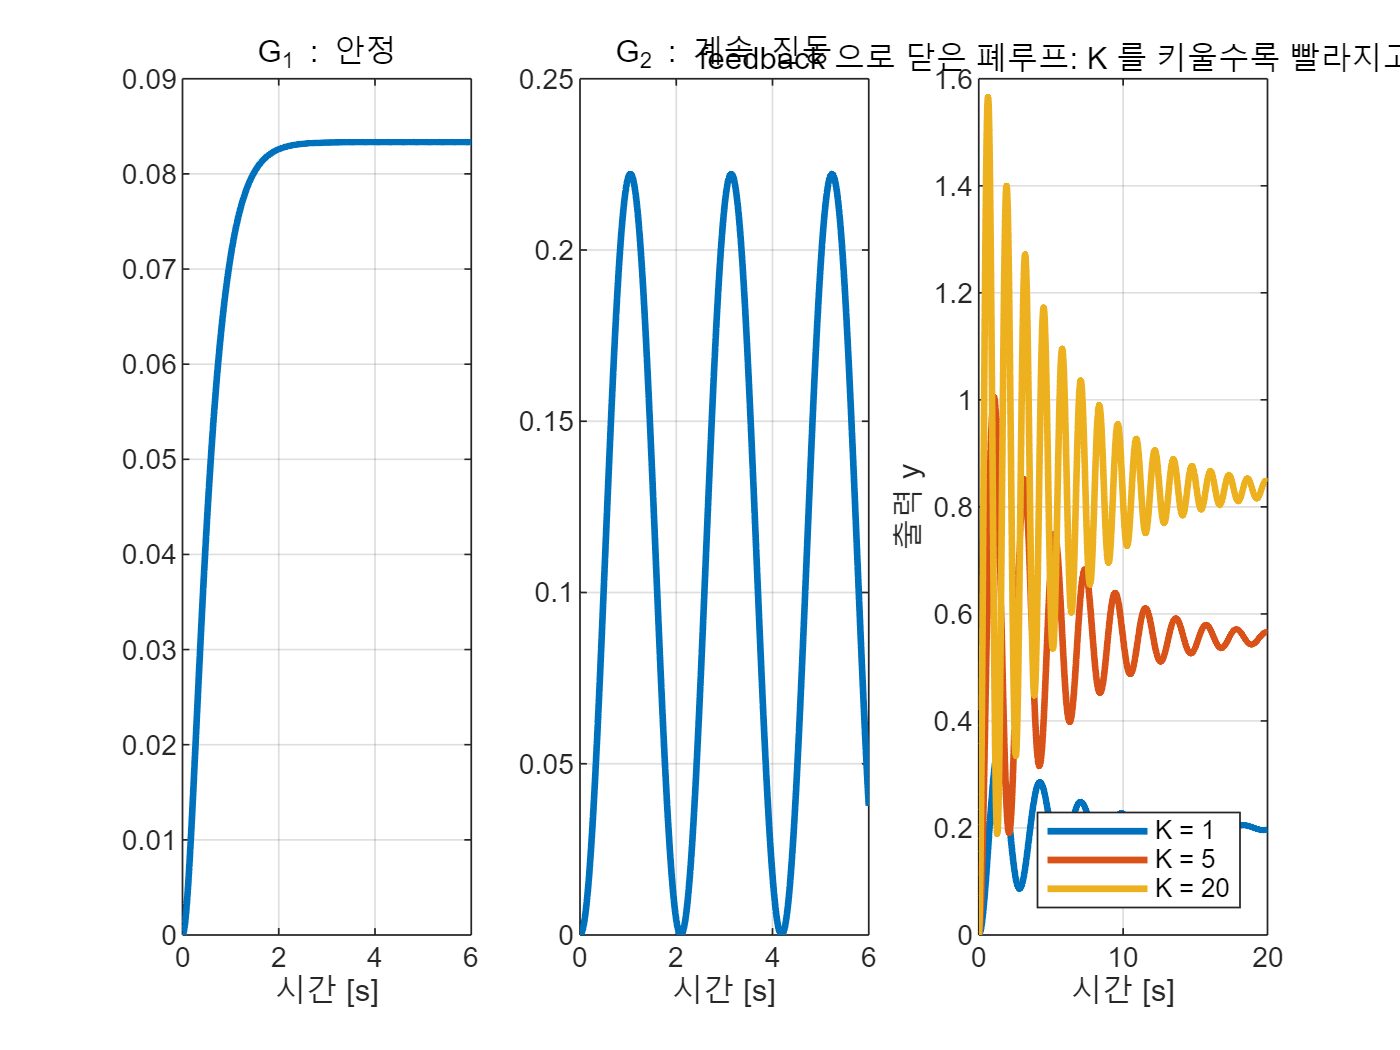

for K = [1 5 20]
    plot(t, step(feedback(K*G_ex,1), t), 'LineWidth', 2); hold on
end
grid on; xlabel('시간 [s]'); ylabel('출력 y')
title('feedback 으로 닫은 폐루프: K 를 키울수록 빨라지고 진동한다')
legend('K = 1','K = 5','K = 20', 'Location','southeast')

## 1-7. `stepinfo` — 응답을 숫자로 요약

- 그림만 보고 "좀 빠르네" 하고 말하면 곤란하다

- **성능은 숫자로 적어야 한다**

말로만 하면 혼동하기 쉽습니다. 각 항목이 응답의 **어느 부분**을 가리키는지 그림으로 봅니다.

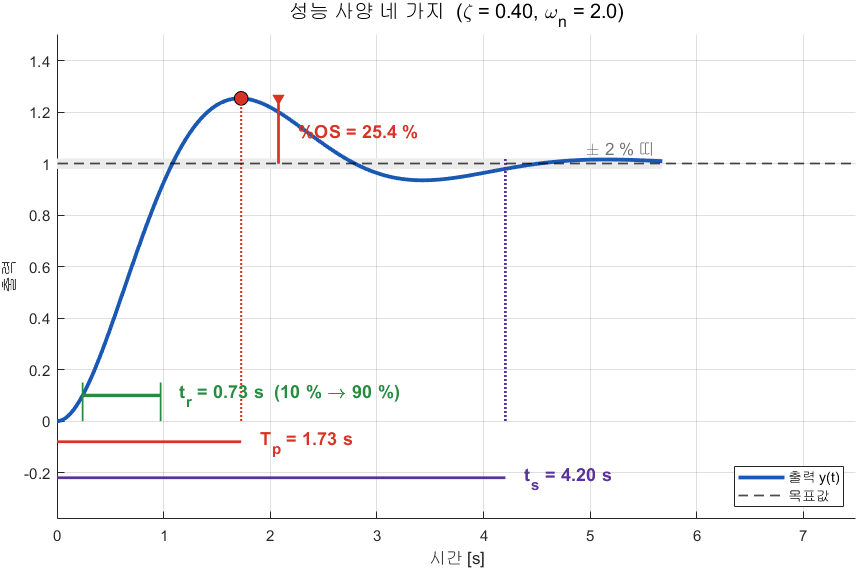

성능 사양 네 가지

**그림 파일** `stepspec.png` — `common/dg_stepspec.m` 의 `dg_stepspec` · 다시 만들려면 `make_figures('stepspec')`

**만드는 곳** — `common/dg_stepspec.m` 을 `dg_stepspec(0.4, 2)` 로 부릅니다. 명령창에서 `dg_stepspec(0.7, 3)` 처럼 직접 불러도 됩니다

그림 해석 — **4주차에서 이 그림을 다시 자세히 봅니다**

오늘은 **이런 것이 있다** 정도만 알면 됩니다. 이 네 숫자를 극점 위치와 잇는 것이 4주차의 주제입니다.

## 1-7-0. 네 항목이 각각 무엇인가

원리

- 새로 계산하지 않는다

- 이미 구한 계단응답 데이터를 훑어 최댓값과 정착 시점을 찾아내는 **후처리**다

- 사람이 자를 대고 그래프에서 읽는 작업을 대신 해 준다고 보면 된다

입출력

- **입력** — 전달함수 (또는 응답 데이터와 시간 벡터)

- **출력** — 여러 지표를 담은 구조체

주요 항목

- `RiseTime` **상승시간** — 최종값의 $10\%$ 에서 $90\%$ 까지 걸린 시간. 얼마나 빠른가

- `Overshoot` **오버슈트** — 최댓값이 최종값을 넘어선 정도 $[\%]$. 얼마나 흔들리는가

- `PeakTime` **첨두시간** — 최댓값에 도달한 시각

- `SettlingTime` **정착시간** — 최종값의 $\pm 2\%$ 안에 들어와 다시 벗어나지 않는 시각

주의

- `SettlingTime` 은 기본이 $2\%$ 기준

- $5\%$ 기준을 쓰려면 `stepinfo(G, 'SettlingTimeThreshold', 0.05)` 로 지정

info = stepinfo(feedback(5*G_ex, 1))

info = 다음 필드를 포함한 struct :
         RiseTime: 0.3659
    TransientTime: 19.0615
     SettlingTime: 19.0615
      SettlingMin: 0.1905
      SettlingMax: 1.0059
        Overshoot: 81.0640
       Undershoot: 0
             Peak: 1.0059
         PeakTime: 1.0472


## 1-7-1. 필요한 항목만 골라 쓰기

- 구조체이므로 점을 찍어 꺼내 쓴다

- 보고서에는 이렇게 정리해서 쓰는 것이 좋다

fprintf('오버슈트  : %.1f %%\n', info.Overshoot);

오버슈트  : 81.1 %


fprintf('상승시간  : %.2f s\n',  info.RiseTime);

상승시간  : 0.37 s


fprintf('정착시간  : %.2f s\n',  info.SettlingTime);

정착시간  : 19.06 s


## 1-8. `lsim` — 아무 입력이나 넣어 보기

- `step` 은 계단입력만 넣는다

- 실제로는 램프, 사인파, 그리고 오늘 다룰 **중간에 갑자기 끼어드는 외란**이 들어온다

원리

- `step` 과 같다. 상태공간으로 바꿔 수치적분한다

- 다만 **입력을 우리가 직접 넘겨 준다**는 점만 다르다

입출력

- **입력** — `lsim(G, u, t)`. `u` 는 각 시각의 입력값 벡터

- **출력** — 각 시각의 출력값 벡터

주의 두 가지

- `u` 와 `t` 의 **길이가 같아야** 한다

- `t` 는 **등간격**이어야 한다. `0:0.01:10` 처럼 만들 것

계단 신호를 손으로 만드는 법

- `(t >= 10)` 이라고 쓰면 조건이 맞는 곳은 $1$, 아닌 곳은 $0$ 인 벡터가 만들어진다

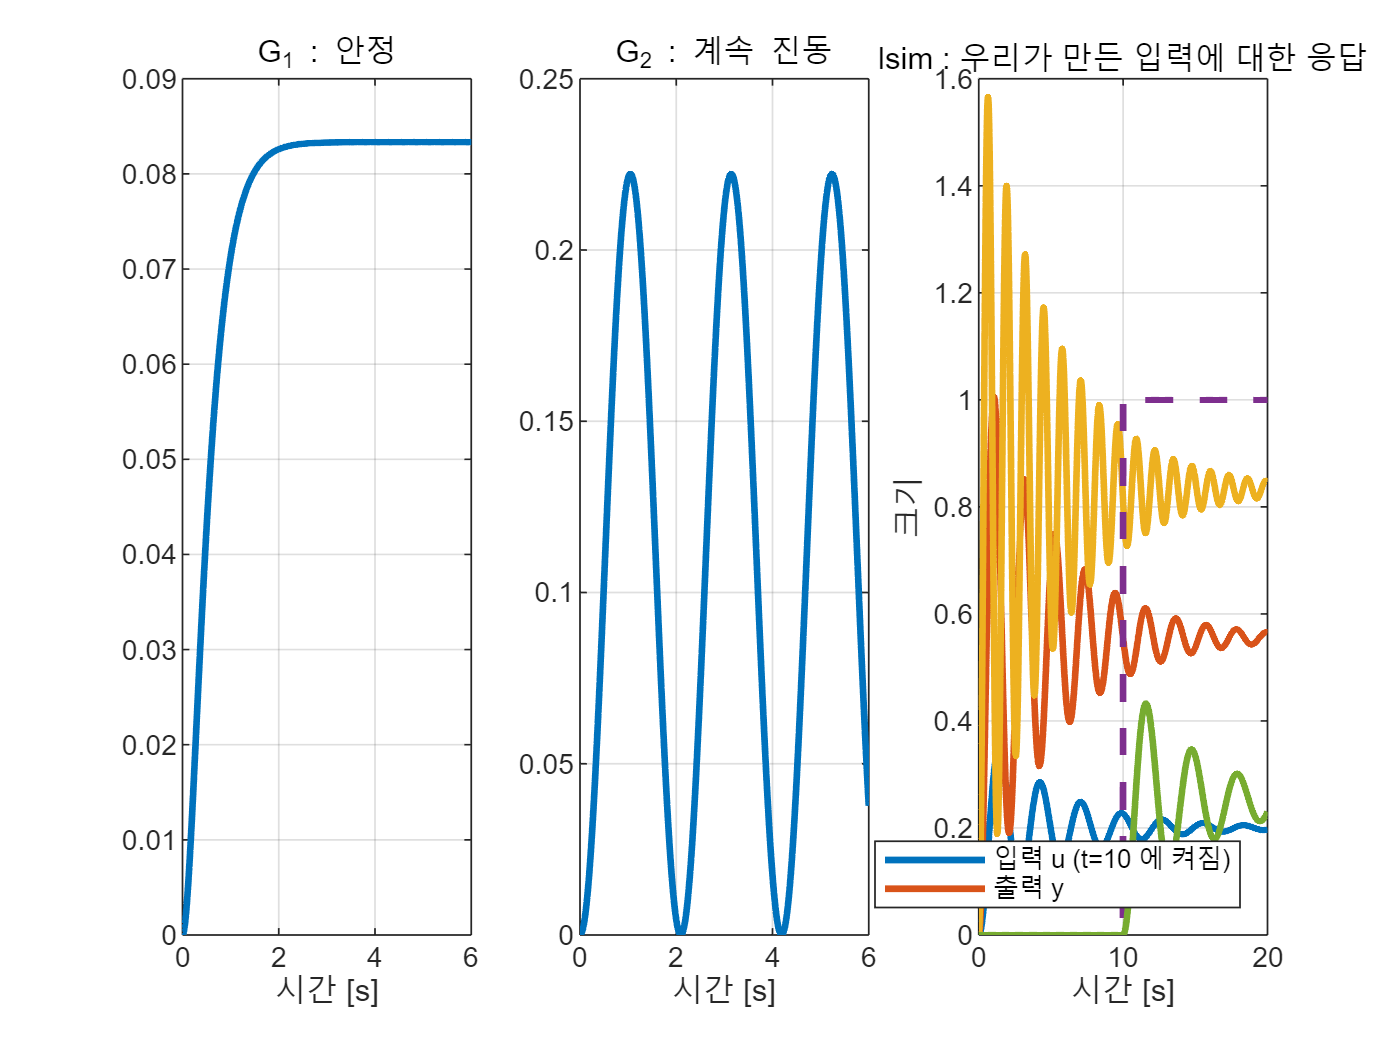

u = 1 * (t >= 10);
y_lsim = lsim(G_ex, u, t);
plot(t, u, '--', 'LineWidth', 2); hold on
plot(t, y_lsim, 'LineWidth', 2); grid on
xlabel('시간 [s]'); ylabel('크기')
title('lsim : 우리가 만든 입력에 대한 응답')
legend('입력 u (t=10 에 켜짐)', '출력 y', 'Location','southeast')

## 1-8-1. 오늘 나온 명령을 여러 가지로 써 본다

같은 명령이라도 **인자를 어떻게 주느냐에 따라 하는 일이 달라집니다.** 실무에서 자주 쓰는 형태를 한자리에 모았습니다. 아래 표를 먼저 읽고, 그다음 코드를 실행해 결과를 대조하십시오.

아래 코드를 실행하면 위 표의 값이 실제로 나옵니다.

s = tf('s');
Gd = 4/(s^2 + 0.8*s + 4);                 % zeta = 0.2, wn = 2

% (1) 만드는 방법 세 가지가 같은 것을 주는지 확인
Ga = tf(4, [1 0.8 4]);
Gb = zpk([], roots([1 0.8 4]).', 4);
fprintf('tf 와 s 연산자의 차이 : %.2e\n', norm(Ga - Gd, inf));

tf 와 s 연산자의 차이 : 0.00e+00


fprintf('tf 와 zpk 의 차이     : %.2e\n', norm(tf(Gb) - Gd, inf));

tf 와 zpk 의 차이     : 1.49e-15



% (2) damp 를 표로 볼 때와 변수로 받을 때
damp(Gd)

                                                                   
          극점                 감쇠             주파수            시정수     
                                       (rad/seconds)    (seconds)  
                                                                   
 -4.00e-01 + 1.96e+00i     2.00e-01       2.00e+00       2.50e+00  
 -4.00e-01 - 1.96e+00i     2.00e-01       2.00e+00       2.50e+00  


[wn_v, z_v] = damp(Gd);
fprintf('변수로 받으면 wn = %.3f, zeta = %.3f\n', wn_v(1), z_v(1));

변수로 받으면 wn = 2.000, zeta = 0.200



% (3) 정착시간 기준을 바꾸면 값이 달라진다
i2 = stepinfo(Gd);
i5 = stepinfo(Gd, 'SettlingTimeThreshold', 0.05);
fprintf('정착시간 : 2%% 기준 %.3f s,  5%% 기준 %.3f s\n', ...
        i2.SettlingTime, i5.SettlingTime);

정착시간 : 2% 기준 9.798 s,  5% 기준 6.870 s



% (4) 되먹임 부호를 틀리면 어떻게 되는가
%     이득이 2 배인 플랜트로 보면 차이가 뚜렷합니다.
G2 = 2*Gd;
T_neg = feedback(G2, 1);
T_pos = feedback(G2, 1, +1);
fprintf('음되먹임 극점 : %s\n', mat2str(round(pole(T_neg).', 3)));

음되먹임 극점 : [-0.4+3.441i -0.4-3.441i]


fprintf('양되먹임 극점 : %s\n', mat2str(round(pole(T_pos).', 3)));

양되먹임 극점 : [-2.44 1.64]


fprintf('   양되먹임 쪽에 실수부가 양수인 극점이 있습니다 -> 발산합니다.\n');

   양되먹임 쪽에 실수부가 양수인 극점이 있습니다 -> 발산합니다.


## 1-8-2. 여러 시스템을 한 그림에 겹치는 세 가지 방법

이 과목에서 가장 자주 하는 일이 **여러 설정의 응답을 겹쳐 보는 것**입니다. 방법이 세 가지 있고, 쓰는 자리가 다릅니다.

**이 과목에서는 두 번째와 세 번째를 씁니다.** 강의노트의 그림처럼 색과 범례를 정확히 맞추려면 값을 직접 받아야 하기 때문입니다.

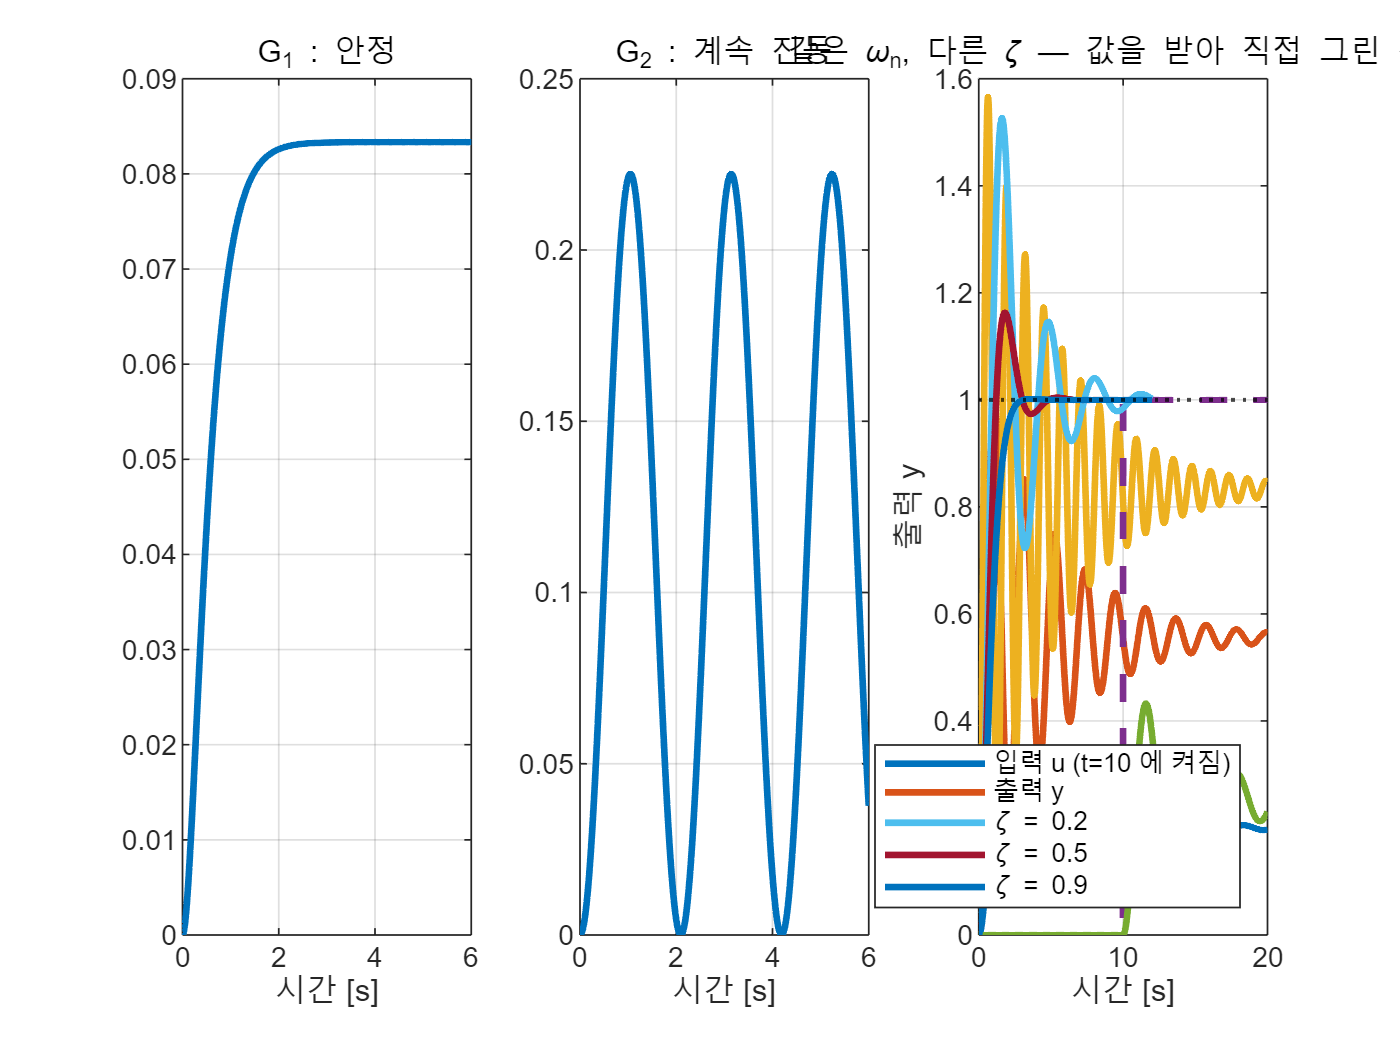

tv = 0:0.01:12;
zs = [0.2 0.5 0.9];
hold on; grid on
for zi = zs
    Gz = 4/(s^2 + 2*zi*2*s + 4);
    plot(tv, step(Gz, tv), 'LineWidth', 2, ...
         'DisplayName', sprintf('\\zeta = %.1f', zi));
end
yline(1, 'k:', 'LineWidth', 1.2, 'HandleVisibility','off');
xlabel('시간 [s]'); ylabel('출력 y'); legend('Location','southeast');
title('같은 \omega_n, 다른 \zeta — 값을 받아 직접 그린 경우');

## 1-9. 1부 요약

- `s = tf('s')` — 전달함수를 식으로 쓸 준비

- `tf(num, den)` — 계수로 전달함수 만들기

- `pole(G)` — 극점. 실수부 음수면 안정

- `damp(G)` — 극점 · $\zeta$ · $\omega_n$ 을 표로

- `step(G, t)` — 계단응답. 출력을 받으면 그림을 안 그림

- `dcgain(G)` — $G(0)$. 충분히 기다렸을 때의 값

- `feedback(G, H)` — $\frac{G}{1+GH}$. 손으로 나누지 말 것

- `stepinfo(G)` — 오버슈트 · 정착시간을 숫자로

- `lsim(G, u, t)` — 임의 입력에 대한 응답

앞으로 추가되는 명령

- 6주차 — `rlocus`, `sgrid`

- 9주차 — `bode`, `margin`

## 2부 — 개루프와 폐루프

이제 위 명령들로 오늘의 본론에 들어갑니다.

## 2-1. 제어 문제의 구조

제어 문제는 언제나 같은 모양입니다.

- **제어 대상** (plant) — 우리가 마음대로 바꿀 수 없는 물리 시스템

- **입력** $u$ — 우리가 넣을 수 있는 것. 힘, 전압, 조타각

- **목표값** $r$ — 우리가 원하는 값

- **출력** $y$ — 실제로 나온 값

제어기 설계란 "$r$ 을 보고 $u$ 를 어떻게 만들 것인가"를 정하는 일이고, 여기서 갈림길이 생깁니다.

- **개루프** — $u$ 를 만들 때 $r$ 만 본다. $y$ 는 쳐다보지 않는다

- **폐루프** — $u$ 를 만들 때 $r$ 과 $y$ 를 같이 본다. 되먹임이 있다

신호가 지나가는 길이 열려 있느냐 닫혀 있느냐에서 나온 이름입니다.

## 2-2. 오늘의 제어 대상 — 질량-스프링-댐퍼

벽에 스프링과 댐퍼로 매달린 물체를 힘으로 밀어 원하는 위치에 세우는 문제입니다. 먼저 그림으로 봅니다. 오른쪽이 자유물체도이고, 거기서 아래 식이 나옵니다.

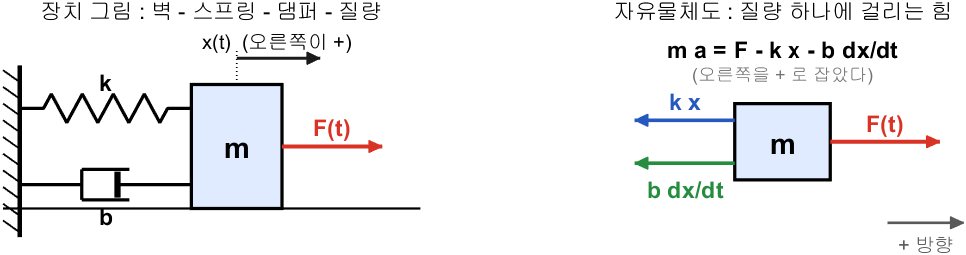

질량-스프링-댐퍼 : 장치 그림과 자유물체도

**그림 파일** `msd_both.png` — `common/dg_msd.m` 의 `dg_msd` · 다시 만들려면 `make_figures('msd_both')`

**만드는 곳** — `common/dg_msd.m` (`make_figures('msd_both')`) **직접 확인해 보려면** — `W01_01_open_vs_closed.m` 의 첫 절이 이 식에서 전달함수를 만듭니다

그림 해석 — **왼쪽에서 부호를 정하고 오른쪽에서 식을 세웁니다**

**자유물체도를 먼저 그리는 이유**가 여기 있습니다. 화살표 방향만 정하면 식은 그대로 옮겨 적으면 됩니다. 그림 없이 식부터 쓰면 부호를 반드시 한 번은 틀립니다.

## 2-2-1. 그림에서 나온 식


$$m\ddot{x} + b\dot{x} + kx = F$$


라플라스 변환하면


$$G(s) = \frac{X(s)}{F(s)} = \frac{1}{ms^2+bs+k}$$


왜 이 시스템인가

- **세상에서 가장 흔한 2차 시스템**이다

- 자동차 서스펜션, 건물의 흔들림, 로봇 관절의 탄성이 모두 이 꼴

표준형과의 대응

- 
$$\omega_n = \sqrt{k/m}$$


- 
$$\zeta = \frac{b}{2\sqrt{mk}}$$


`plant_msd` 는 이 과목에서 준비해 둔 함수로, 전달함수와 파라미터 구조체를 돌려줍니다.

[G, p] = plant_msd();
G


G =
 
  입력 "F"에서 출력 "x"(으)로:
         1
  ---------------
  s^2 + 0.2 s + 1
 
연속시간 전달 함수입니다.
모델 속성


fprintf('고유진동수 = %.2f rad/s,  감쇠비 = %.2f,  DC 이득 = %.2f\n', ...
        p.wn, p.zeta, dcgain(G));

고유진동수 = 1.00 rad/s,  감쇠비 = 0.10,  DC 이득 = 1.00


## 2-3. 아무 제어도 하지 않으면

- 제어기 없이 힘 $1\,\mathrm{N}$ 을 그대로 넣어 본다

- $\zeta = 0.1$ 로 작아서 한참 출렁이다가 겨우 자리를 잡는다

- **이 출렁임이 오늘 내내 따라다닌다**

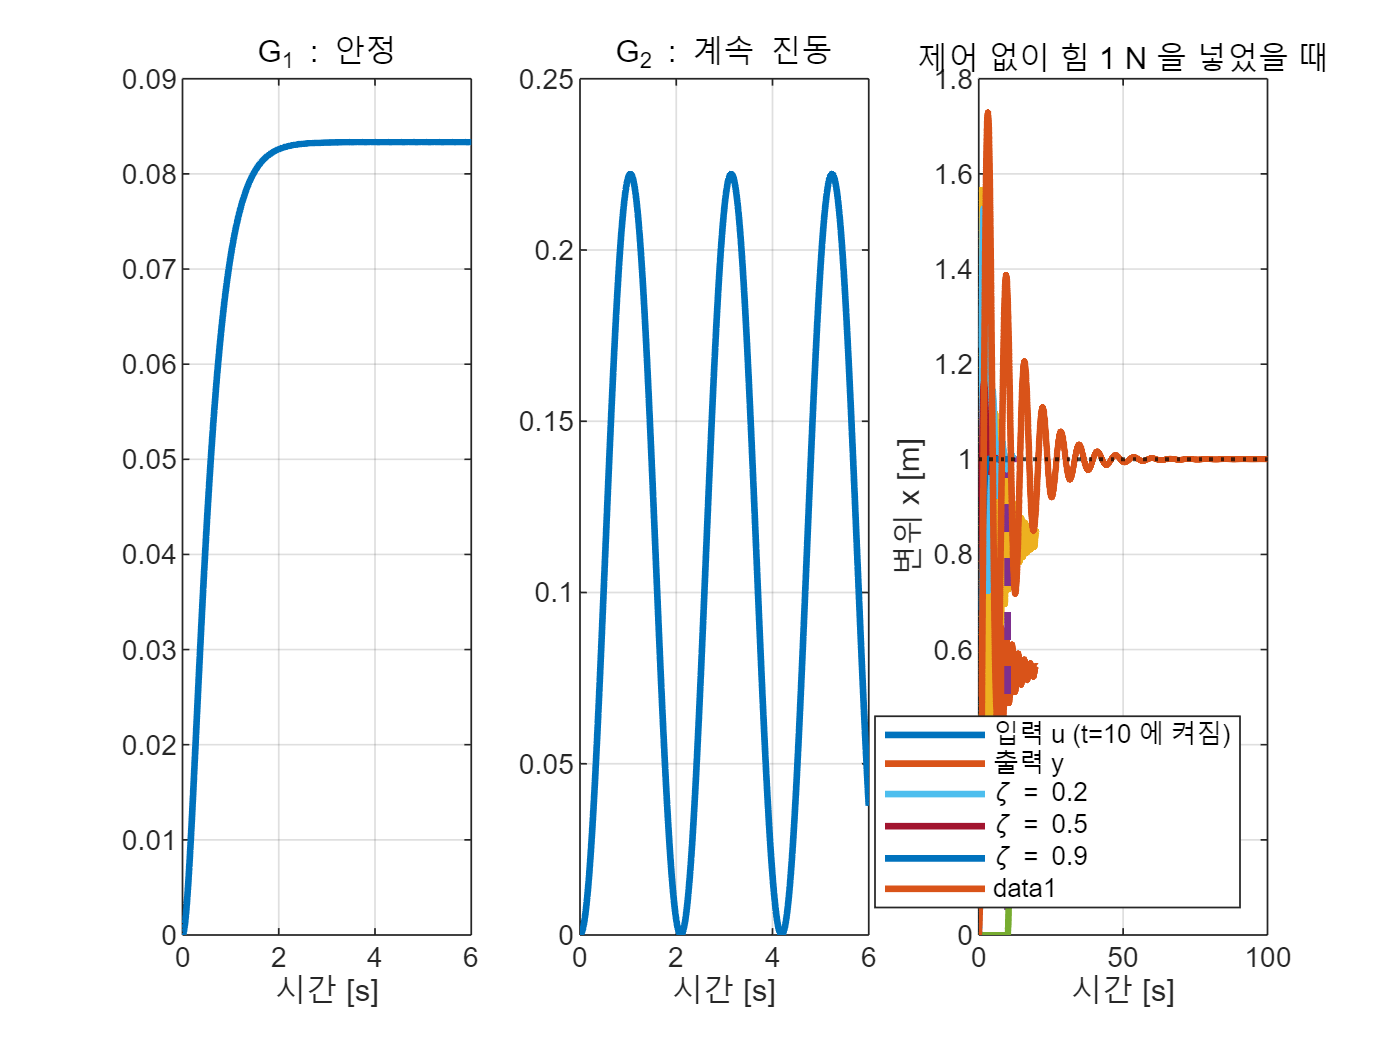

t = 0:0.01:100;
plot(t, step(G, t), 'LineWidth', 2); grid on
xlabel('시간 [s]'); ylabel('변위 x [m]')
title('제어 없이 힘 1 N 을 넣었을 때')

## 3. 개루프 제어 — 미리 계산해서 넣기

아이디어는 단순합니다 — **출력이 얼마가 될지 아니까 역으로 계산해서 넣자.**

정상상태에서 $y = G(0)u$ 이므로 $y=r$ 이 되게 하려면


$$u = \frac{r}{G(0)} = K_{ff}\,r$$


- 이 $K_{ff}$ 를 **피드포워드 이득**이라 한다

- 앞에서 배운 `dcgain` 이 여기서 쓰인다

여기서 꼭 짚을 점

- 이 계산은 $G(0)$** 를 정확히 안다는 가정** 위에 서 있다

- 그 가정이 깨지는 순간 개루프는 무너진다

- 7절에서 실제로 무너뜨려 본다

미리 한 장으로 보면 이렇습니다.

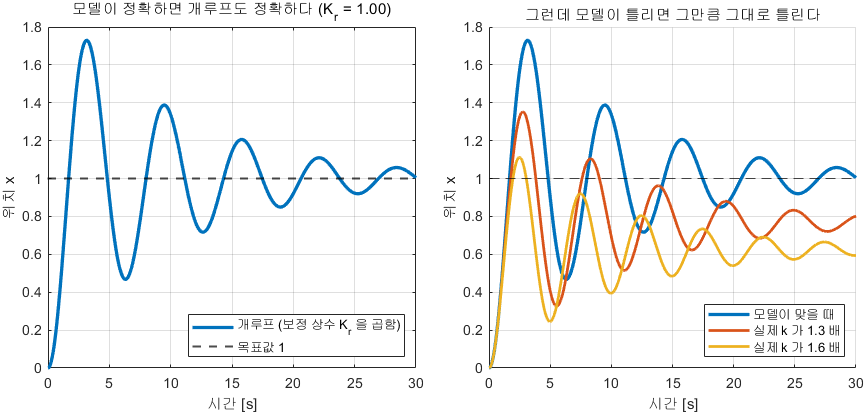

모델이 맞으면 완벽하고, 틀리면 그만큼 그대로 틀린다

**그림 파일** `w01_ol_fail.png` — `make_figures.m` 의 `fig_w01_openloop_fail` · 다시 만들려면 `make_figures('w01_ol_fail')`

**만드는 곳** — `make_figures.m` 의 `fig_w01_openloop_fail` **직접 바꿔 보려면** — `W01_02_model_uncertainty.m` 에서 실제 $k$ 의 배수를 $1.3$, $1.6$ 말고 다른 값으로 바꿔 실행

그림 해석

**오른쪽 그림이 개루프의 한계입니다.** 계산은 맞았는데 세상이 달랐습니다. 그리고 개루프는 그 사실을 **알 방법조차 없습니다.** 출력을 보지 않기 때문입니다.

왼쪽은 모델이 정확할 때입니다. **개루프인데도 목표값에 정확히 닿습니다.** 개루프가 늘 나쁜 것이 아니라는 점을 여기서 분명히 해 두겠습니다.

오른쪽이 문제입니다. 스프링 상수 $k$ 가 예상보다 $1.3$ 배, $1.6$ 배 뻣뻣했다면 출력이 정확히 그 비율만큼 모자랍니다. **오차를 볼 방법이 없으니 고칠 수도 없습니다.**


$$k \rightarrow 1.5\,k \quad\Rightarrow\quad G(0) = \frac{1}{k} \rightarrow \frac{1}{1.5k} \quad\Rightarrow\quad y_{ss} = K_{ff}\,G_{real}(0) = \frac{1}{1.5} \approx 0.667$$


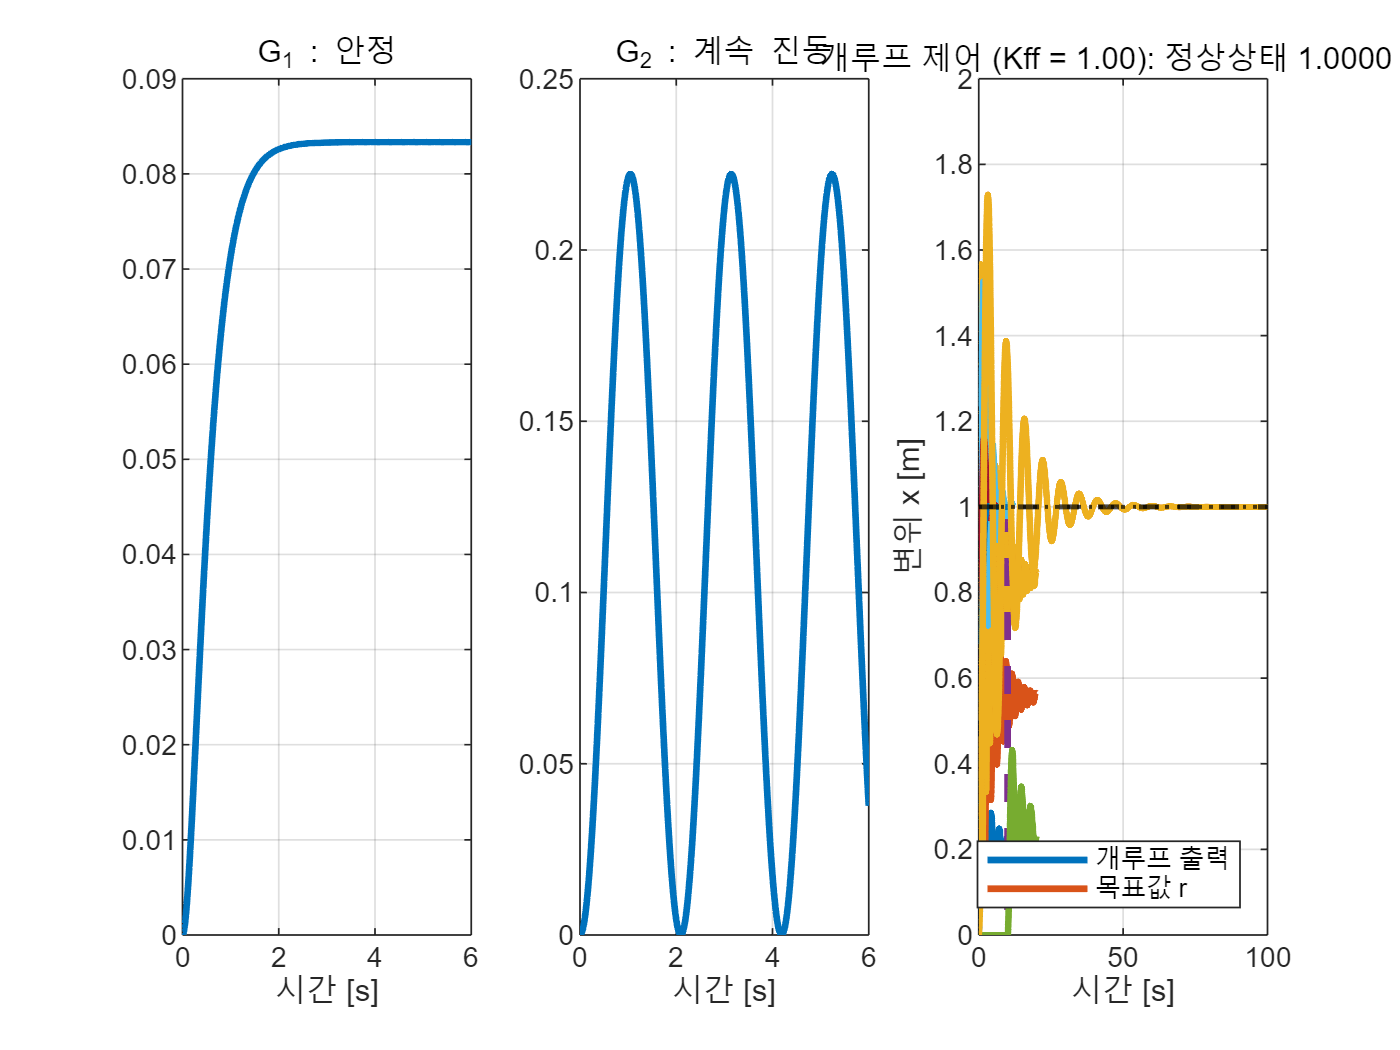

r   = 1;
Kff = 1 / dcgain(G);
y_open = step(r*Kff*G, t);
plot(t, y_open, 'LineWidth', 2); hold on
yline(r, 'k--', 'LineWidth', 1.5); grid on
xlabel('시간 [s]'); ylabel('변위 x [m]')
title(sprintf('개루프 제어 (Kff = %.2f): 정상상태 %.4f m', Kff, y_open(end)))
legend('개루프 출력', '목표값 r', 'Location','southeast'); ylim([0 2])

## 3-1. 여기서 놀라야 합니다

- 개루프인데 **목표값에 정확히 도달**했다

- 즉 "피드백이 없으면 오차가 난다"는 말은 **사실이 아니다**

- 모델이 정확하고 외란이 없다면 개루프로도 완벽하게 제어할 수 있다

우리 주변의 개루프 제어

- 전자레인지 타이머

- 신호등

- 세탁기 급수 시간

결과를 재지 않고 "이만큼 하면 되겠지" 하고 정해 둔 대로 실행합니다. 그렇다면 왜 제어공학 수업의 대부분이 피드백을 다루는가?

## 4. 폐루프 비례제어

매 순간 출력을 재서 오차를 계산하고, 그 오차에 비례하는 힘을 넣습니다.


$$e(t) = r - y(t), \qquad u(t) = K\,e(t)$$


폐루프 전달함수는 `feedback(K*G, 1)` 로 구합니다.


$$T(s) = \frac{KG(s)}{1+KG(s)}, \qquad T(0) = \frac{K}{1+K}$$


- $K$ 가 클수록 $1$ 에 가까워진다

- 그러나 **절대로 **$1$** 이 되지는 못한다**

왜 오차가 남는가

- 비례제어는 **오차가 있어야만 힘을 낸다**

- 오차가 $0$ 이면 힘도 $0$

- 그런데 이 플랜트는 스프링이 있어서 힘이 $0$ 이면 원점으로 되돌아간다

- 즉 스프링을 버틸 힘을 내려면 오차가 조금은 남아 있어야 한다

- **오차가 제어기의 연료인 셈이다**

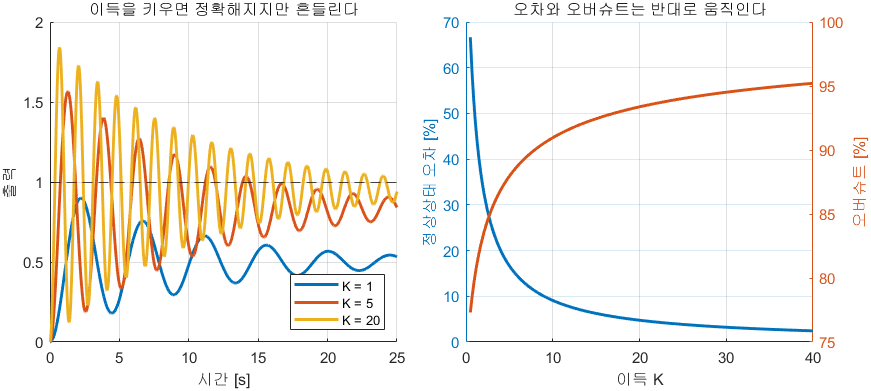

이득을 키우면 정확해지지만 흔들린다

**그림 파일** `w01_gain_sweep.png` — `make_figures.m` 의 `fig_gain_sweep` · 다시 만들려면 `make_figures('w01_gain_sweep')`

**만드는 곳** — `make_figures.m` 의 `fig_gain_sweep` **직접 바꿔 보려면** — `W01_01_open_vs_closed.m` 에서 `K` 목록을 바꿔 실행

그림 해석 — **오른쪽 그림의 두 세로축 색을 보십시오**

**오른쪽 그림 하나가 이 과목 전체의 축소판입니다.** 하나를 얻으려면 하나를 내줘야 합니다. 4주차에서 이 맞바꿈을 숫자로 적는 법을 배우고, 6주차부터는 그 숫자를 보고 $K$ 를 고릅니다.

for K = [1 3 9]
    T = feedback(K*G, 1);
    plot(t, step(r*T, t), 'LineWidth', 2); hold on
    fprintf('K = %d : 정상상태 %.4f (이론 %.4f), 오차 %.1f %%\n', ...
            K, dcgain(r*T), K/(1+K), 100*(1 - K/(1+K)));
end

K = 1 : 정상상태 0.5000 (이론 0.5000), 오차 50.0 %
K = 3 : 정상상태 0.7500 (이론 0.7500), 오차 25.0 %
K = 9 : 정상상태 0.9000 (이론 0.9000), 오차 10.0 %


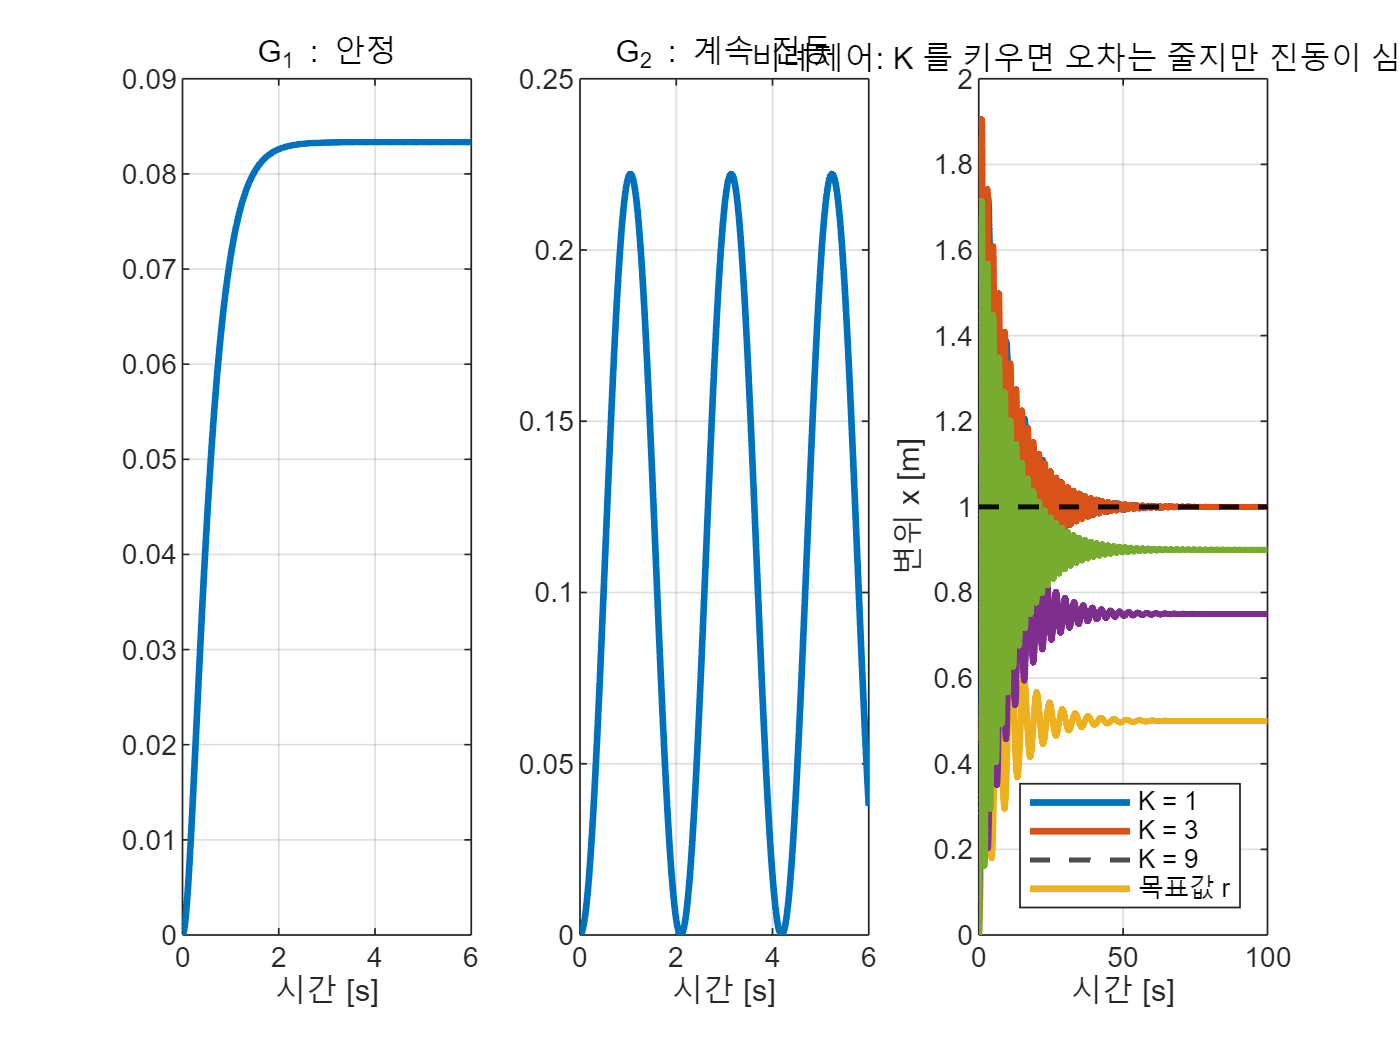

yline(r, 'k--', 'LineWidth', 1.5); grid on
xlabel('시간 [s]'); ylabel('변위 x [m]')
title('비례제어: K 를 키우면 오차는 줄지만 진동이 심해진다')
legend('K = 1','K = 3','K = 9','목표값 r', 'Location','southeast'); ylim([0 2]); hold off;

## 4-1. 이대로면 개루프의 완승입니다

- 개루프는 오차가 $0$

- 폐루프는 $10\sim50\%$ 나 틀리고 진동까지 심함

- 이 그림만 보면 피드백을 쓸 이유가 없어 보인다

그런데 **이 비교는 불공정했습니다**

- 개루프에는 $K_{ff}$ 라는 보정 상수를 붙여 줬다

- 폐루프에는 아무것도 안 붙였다

- 조건을 맞춰 줍시다

## 5. 공정하게 — 폐루프에도 보정 상수를 붙이자

폐루프에도 상수를 하나 곱해 정상상태를 맞춥니다.


$$K_r = \frac{1}{T(0)} = \frac{1+K}{K}$$


- 여기서도 `dcgain` 이 쓰인다

- 폐루프 전달함수의 DC 이득의 역수를 취하면 된다

- 이 아이디어는 **13주차 상태궤환 제어**에서 똑같은 $K_r$ 이라는 이름으로 다시 등장한다

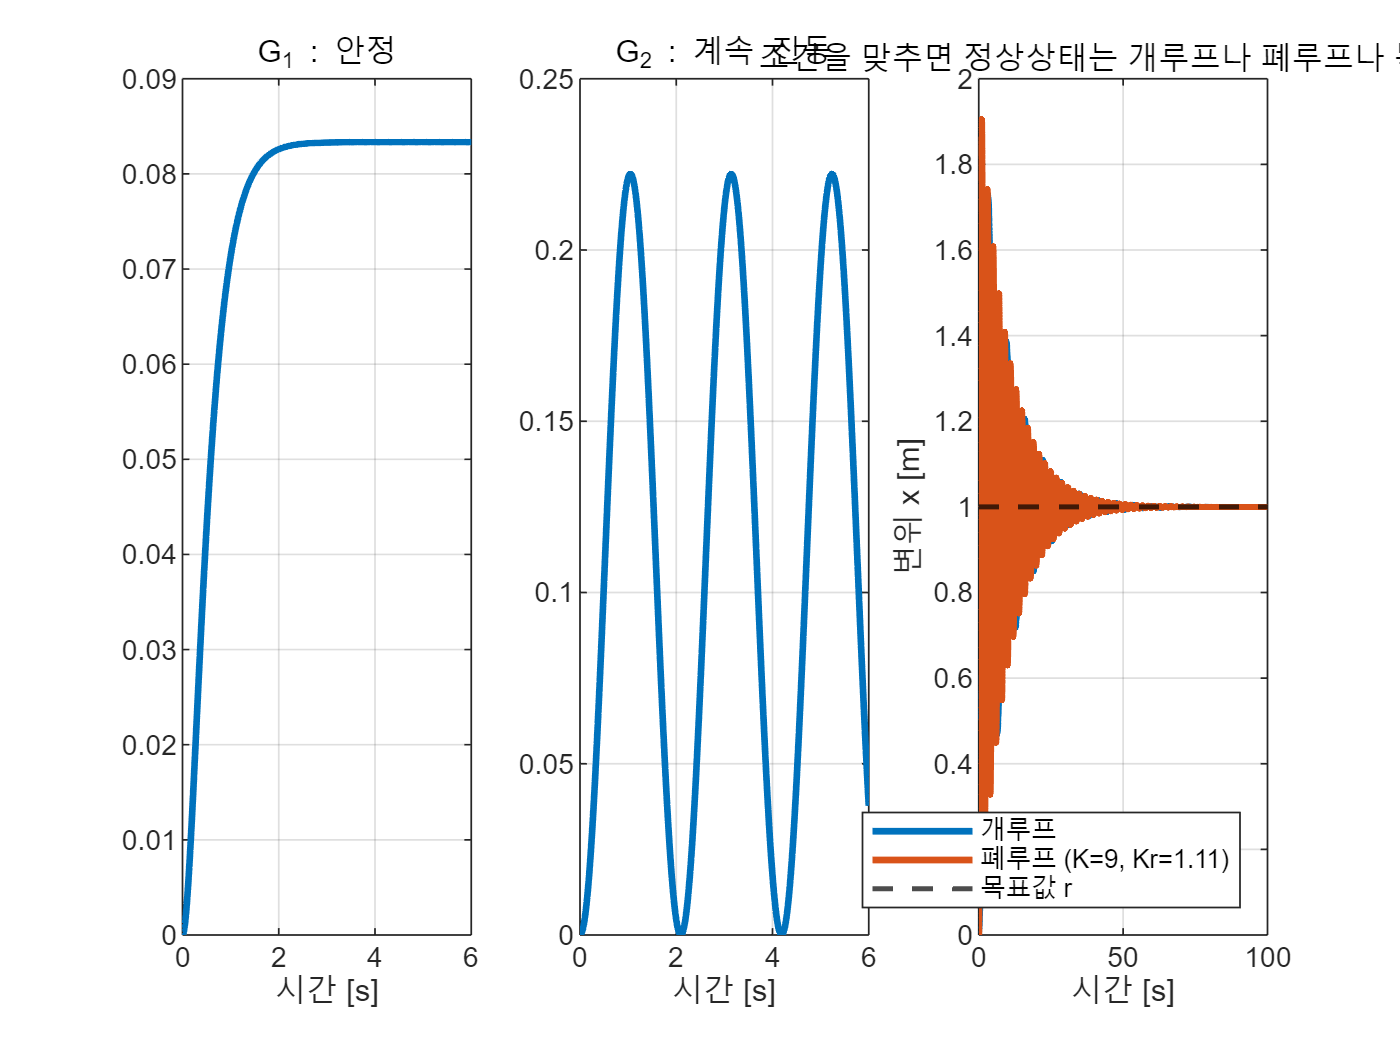

K  = 9;
T  = feedback(K*G, 1);
Kr = 1 / dcgain(T);
y_close = step(r*Kr*T, t);
plot(t, y_open, 'LineWidth', 2); hold on
plot(t, y_close, 'LineWidth', 2)
yline(r, 'k--', 'LineWidth', 1.5); grid on
xlabel('시간 [s]'); ylabel('변위 x [m]')
title('조건을 맞추면 정상상태는 개루프나 폐루프나 똑같다')
legend('개루프', sprintf('폐루프 (K=%d, Kr=%.2f)', K, Kr), '목표값 r', ...
       'Location','southeast'); ylim([0 2])

## 6. 결정적 장면 하나 — 외란

무승부 상태에서 현실을 한 스푼 넣어 봅니다.

- 바람, 마찰, 누가 툭 미는 힘

- 이것을 **외란** $d$ 라 하고 플랜트 입력단에 더해진다

- 즉 플랜트가 실제로 받는 힘은 $u+d$

식을 세우기 전에 $u$** 와 **$d$** 가 어디서 만나는지** 그림으로 확인합니다. 이 자리를 잘못 잡으면 뒤의 유도가 통째로 틀립니다.

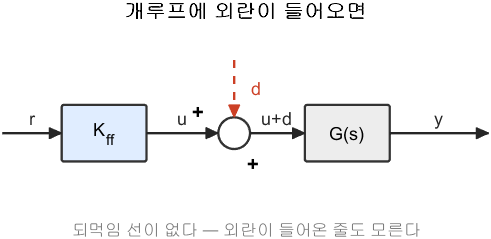

개루프 — 외란이 들어온 줄도 모른다

**그림 파일** `loop_dist_open.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_dist_open')`

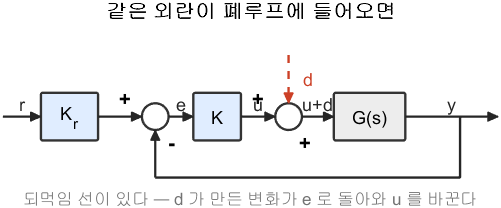

폐루프 — 같은 자리에 같은 외란이 들어온다

**그림 파일** `loop_dist_closed.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_dist_closed')`

**만드는 곳** — `common/dg_loop.m` 을 `dg_loop('dist_open', ...)` 과 `dg_loop('dist_closed', ...)` 로 부릅니다 **직접 확인해 보려면** — `W01_01_open_vs_closed.m` 의 외란 실험 절

그림 해석 — **두 그림을 위아래로 놓고 같은 자리를 짚어 가며 읽으십시오**

**첫 그림에서 **$d$** 가 들어온 뒤 **$y$** 까지 가는 길에 아무 장치도 없습니다.** 그래서 외란이 $G$ 를 그대로 통과합니다. 둘째 그림에는 되먹임 선이 있어 $d$ 가 만든 변화가 다시 $e$ 로 돌아와 $u$ 를 바꿉니다. 이 차이가 전부입니다.

이제 각각의 출력이 어떻게 나오는지 **한 줄씩 따라가 봅니다.** 외우지 말고 **그림의 신호를 따라가면** 됩니다. 방법은 언제나 같습니다.

- 출력 $y$ 에서 시작해 **거슬러 올라가며** 식을 적는다

- $y$ 가 양변에 나오면 **한쪽으로 모은다**

- $y$ 로 묶어 나눈다

**개루프** — 제어기가 출력을 보지 않으므로 거슬러 올라갈 것이 없습니다.


$$u = K_{ff}\,r$$


플랜트가 실제로 받는 힘은 $u + d$ 이므로


$$y_{\rm open} = G\,(u + d) = G\,(K_{ff}\,r + d) = G K_{ff}\,r + G\,d$$


**한 줄로 끝났습니다.** $y$ 가 오른쪽에 다시 나오지 않기 때문입니다.

**폐루프** — 여기서는 $y$ 가 되돌아오므로 이야기가 달라집니다. 신호를 따라가면 세 줄입니다.


$$e = K_r\,r - y, \qquad u = K\,e, \qquad y = G\,(u + d)$$


마지막 식에 앞의 둘을 차례로 넣습니다.


$$y = G\left(K(K_r r - y) + d\right) = G K K_r\,r - G K\,y + G\,d$$


**여기서 **$y$** 가 양변에 나옵니다.** 왼쪽으로 모읍니다.


$$y + G K\,y = G K K_r\,r + G\,d \qquad\Rightarrow\qquad (1 + KG)\,y = G K K_r\,r + G\,d$$


양변을 $(1+KG)$ 로 나누면 끝입니다.


$$y_{\rm closed} = \frac{KG}{1+KG}\,K_r\,r + \frac{G}{1+KG}\,d = K_r T\,r + \frac{G}{1+KG}\,d$$


여기서 $T = \frac{KG}{1+KG}$ 는 1-6절에서 `feedback` 이 계산해 준 그것입니다.

$(1+KG)$** 가 어디서 나왔는지 보십시오.** $y$ 를 한쪽으로 모으는 그 한 걸음에서 나왔습니다. 되먹임 선이 없으면 이 항이 생기지 않습니다. 오늘 이후 학기 내내 나오는 $1+KG$ 는 전부 이 자리에서 온 것입니다.

두 식을 나란히 놓으면 이렇습니다.

외란이 붙은 항을 보십시오.

- **개루프** — $Gd$ 가 그대로 살아 있다

- **폐루프** — 분모에 $(1+KG)$ 가 붙어 그만큼 줄어든다

개루프가 외란을 못 잡는 이유는 허무할 정도로 단순합니다.

- **출력을 보지 않으니 외란이 들어온 줄도 모른다**

계산 방법

- `lsim` 으로 목표값 신호와 외란 신호를 각각 넣고 두 응답을 더한다

- 더해도 되는 이유는 선형 시스템이기 때문이며, 이를 **중첩의 원리**라 한다

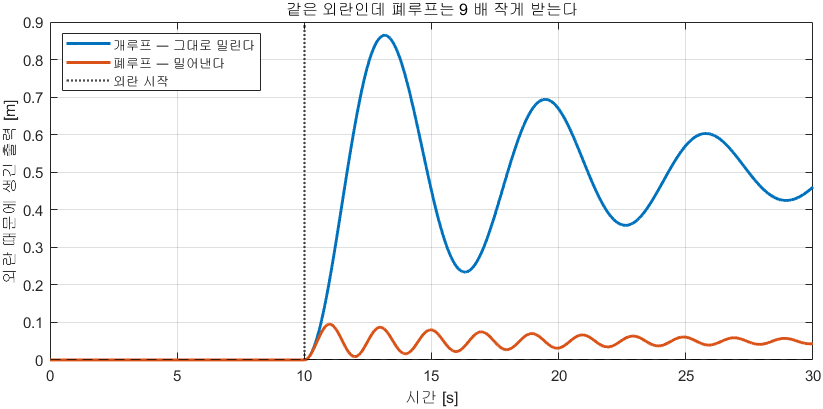

같은 외란인데 폐루프는 훨씬 작게 받는다

**그림 파일** `w01_disturbance.png` — `make_figures.m` 의 `fig_disturbance` · 다시 만들려면 `make_figures('w01_disturbance')`

**만드는 곳** — `make_figures.m` 의 `fig_disturbance` **직접 바꿔 보려면** — `W01_01_open_vs_closed.m` 의 외란 실험 절에서 $K$ 를 바꾸면 두 곡선의 간격이 달라집니다

그림 해석

$9$** 라는 숫자가 어디서 왔는지** 확인해 봅니다.

정상상태에서 외란이 출력에 얼마나 나오는지는 이렇게 됩니다.


$$\text{개루프} : \; \frac{y}{d} = G(0) \qquad\qquad \text{폐루프} : \; \frac{y}{d} = \frac{G(0)}{1 + K\,G(0)}$$


두 값의 비가 $1 + KG(0)$ 입니다. 이 플랜트는 $G(0) = 1$ 이고 그림은 $K = 9$ 로 그렸으므로 **정확히 **$10$** 배**가 나와야 합니다.

그림에 $9$ 배로 적힌 것은 **정상상태가 아니라 봉우리끼리 견준 값**이라 그렇습니다. 과도응답 중에는 조금 다르게 나옵니다. 정상상태로 재면 정확히 $10$ 입니다. 다음 절에서 그 식을 유도합니다.

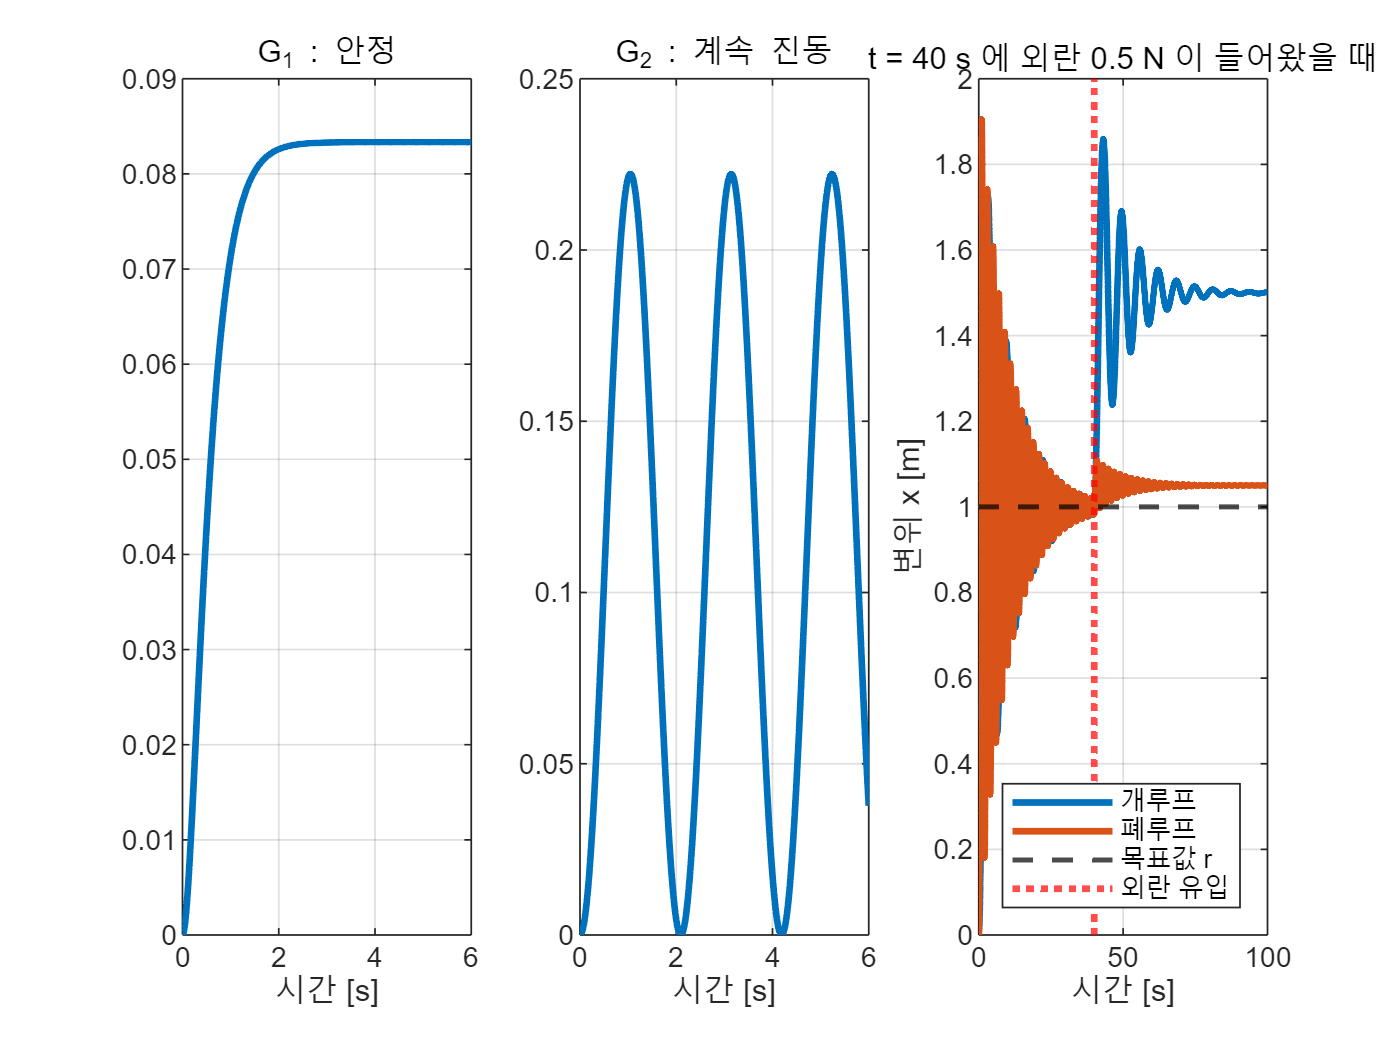

d = 0.5; t_d = 40;
u_ref = r*ones(size(t));
u_dis = d*(t >= t_d);
y_open_d  = lsim(Kff*G, u_ref, t) + lsim(G, u_dis, t);
y_close_d = lsim(Kr*T, u_ref, t) + lsim(feedback(G,K), u_dis, t);
plot(t, y_open_d, 'LineWidth', 2); hold on
plot(t, y_close_d, 'LineWidth', 2)
yline(r, 'k--', 'LineWidth', 1.5); xline(t_d, 'r:', 'LineWidth', 2); grid on
xlabel('시간 [s]'); ylabel('변위 x [m]')
title(sprintf('t = %d s 에 외란 %.1f N 이 들어왔을 때', t_d, d))
legend('개루프', '폐루프', '목표값 r', '외란 유입', 'Location','southeast'); ylim([0 2])

## 6-1. 숫자로 확인

- 외란 억제비의 이론값은 $\frac{1}{1+KG(0)}$

- $K=9$, $G(0)=1$ 이므로 $\frac{1}{10}$

- 즉 오차가 **10분의 1** 로 줄어야 한다

fprintf('개루프 최종 오차 : %+.4f m\n', r - y_open_d(end));

개루프 최종 오차 : -0.5012 m


fprintf('폐루프 최종 오차 : %+.4f m\n', r - y_close_d(end));

폐루프 최종 오차 : -0.0500 m


fprintf('줄어든 비율      : %.1f 배   (이론값 %.0f)\n', ...
        abs((r-y_open_d(end))/(r-y_close_d(end))), 1+K*dcgain(G));

줄어든 비율      : 10.0 배   (이론값 10)


## 7. 결정적 장면 둘 — 모델이 틀렸을 때

이번에는 외란을 완전히 없애고, 대신 **우리가 아는 모델 자체를 틀리게** 만듭니다.

현실에서 모델은 반드시 틀립니다.

- 스프링 상수는 온도에 따라 변한다

- 부품마다 개체차가 있다

- 배는 화물을 실으면 질량이 변한다

- 마찰계수는 애초에 정확히 알 수가 없다

상황 설정

- 설계할 때는 $k=1$ 이라 믿고 제어기를 만들었다

- 실제 스프링은 $k=1.5$ 로 $50\%$ 더 뻣뻣했다

- **우리는 이 사실을 모른다.** 제어기는 이미 $k=1$ 기준으로 정해져 버렸다

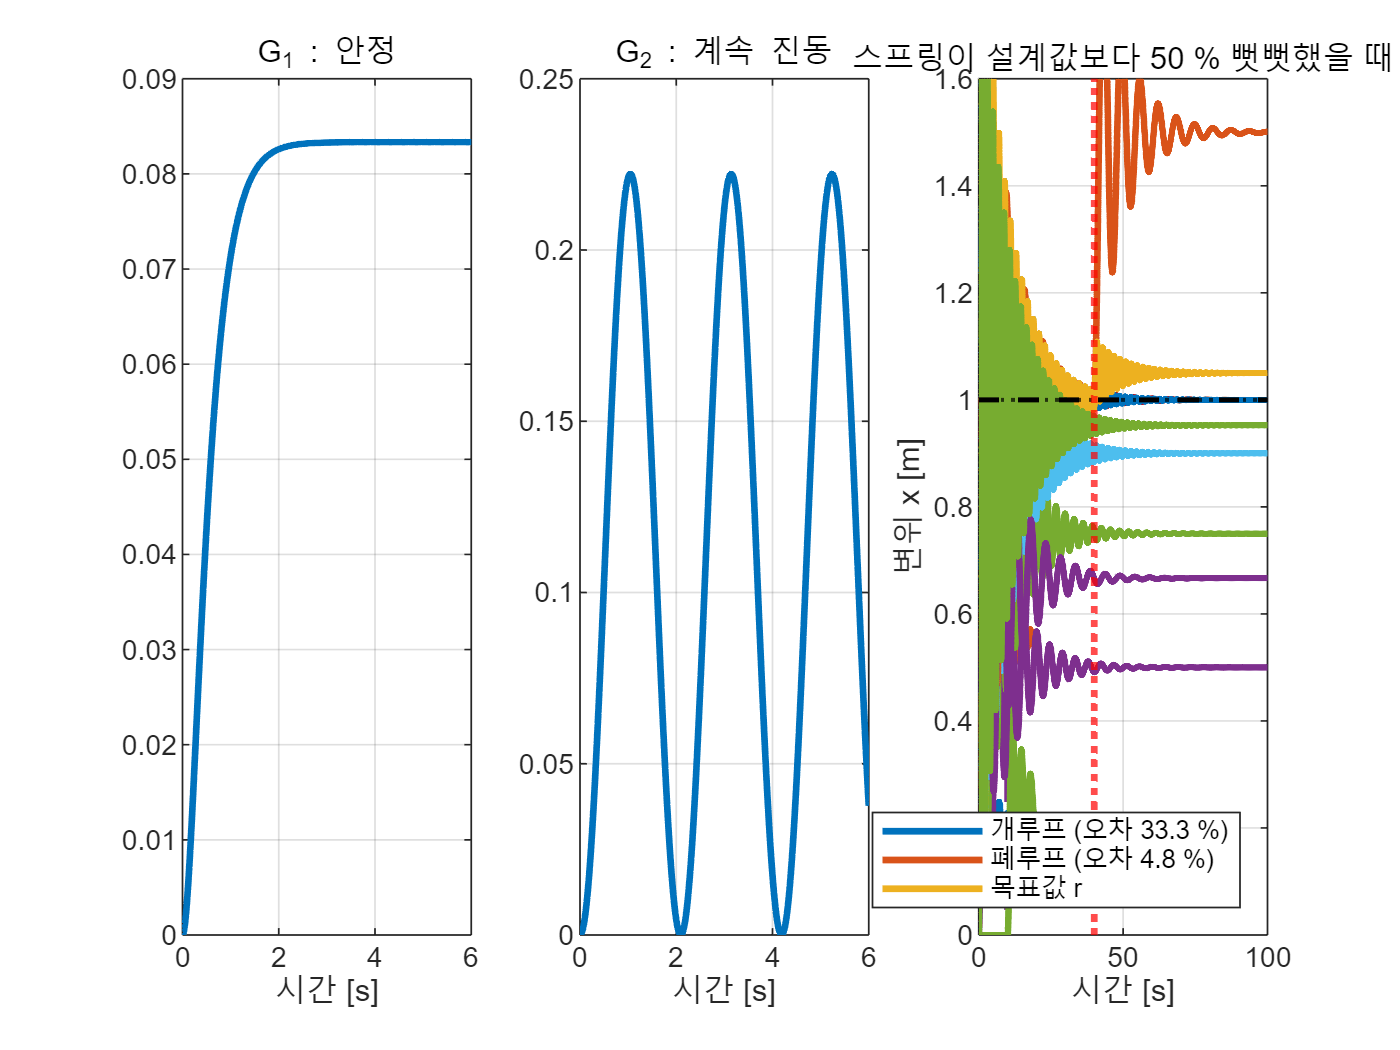

G_design = plant_msd([], [], 1.0);
G_true   = plant_msd([], [], 1.5);
Kff_d = 1/dcgain(G_design);
Kr_d  = 1/dcgain(feedback(K*G_design, 1));
y_open_u  = step(r*Kff_d*G_true, t);
y_close_u = step(r*Kr_d*feedback(K*G_true,1), t);
plot(t, y_open_u, 'LineWidth', 2); hold on
plot(t, y_close_u, 'LineWidth', 2)
yline(r, 'k--', 'LineWidth', 1.5); grid on
xlabel('시간 [s]'); ylabel('변위 x [m]')
title('스프링이 설계값보다 50 % 뻣뻣했을 때')
legend(sprintf('개루프 (오차 %.1f %%)', 100*abs(r-y_open_u(end))), ...
       sprintf('폐루프 (오차 %.1f %%)', 100*abs(r-y_close_u(end))), ...
       '목표값 r', 'Location','southeast'); ylim([0 1.6])

## 8. 두 장면을 하나로 묶는 것

여기서 재미있는 일이 벌어집니다.

- 외란을 얼마나 잘 밀어내는지

- 모델이 틀려도 얼마나 잘 버티는지

- 둘 다 **똑같은 값 하나**로 결정된다


$$S = \frac{1}{1 + KG}$$


왜 같은 값인가

- 원리가 하나이기 때문

- 무슨 이유로든 출력이 목표에서 벗어나면 오차가 생긴다

- 제어기는 그 오차를 보고 힘을 더 낸다

- 원인이 외란이든 모델 오차든 **제어기 입장에서는 똑같이 오차일 뿐**이다

말로만 하면 안 믿깁니다. **두 경우를 각각 계산해서 같은 식이 나오는지 봅니다.**

## 8-A. 첫째 — 외란 쪽에서 $S$ 가 나오는 과정

6절에서 이미 얻었습니다. 외란에서 출력으로 가는 전달함수는


$$\frac{y}{d} = \frac{G}{1+KG} = G \cdot \frac{1}{1+KG} = G \cdot S$$


개루프에서는 같은 자리가 $G$ 였습니다. 그러므로


$$\frac{(\text{폐루프가 받는 외란})}{(\text{개루프가 받는 외란})} = \frac{G S}{G} = S = \frac{1}{1+KG}$$


**외란이 정확히 **$S$** 배로 줄어듭니다.**

## 8-B. 둘째 — 모델 오차 쪽. **먼저 숫자로 봅니다**

이쪽은 미분이 나옵니다. 식부터 보면 "왜 하필 이렇게 미분하지?" 싶으므로 **먼저 숫자로 무슨 일이 일어나는지 보고** 그다음에 식을 세웁니다.

우리 플랜트는 $G(0) = 1$ 이고 $K = 9$ 입니다.

먼저 **부품의 오차가 **$G$** 의 오차로 어떻게 넘어오는지** 확인하고 갑니다. MSD 의 직류이득은 $G(0) = 1/k$ 이므로 **스프링과 반대로 움직입니다.**

그러니 "스프링이 뻣뻣하다" 와 "$G$ 가 크다" 는 **같은 말이 아닙니다.** 헷갈리기 쉬운 자리이므로 여기서 한 번 짚고 갑니다.

아래에서는 스프링이 예상보다 **조금 물러서** $G$ 가 $1\%$** 커졌다**고 두겠습니다.

**개루프는 **$1\%$** 틀리면 **$1\%$** 틀립니다.** 그대로 옵니다. **폐루프는 **$1\%$** 틀려도 **$0.1\%$** 밖에 안 틀립니다.** 열 배 덜 틀립니다.

그리고 $\frac{1}{1+KG(0)} = \frac{1}{1+9} = 0.1$ 입니다. $0.1$** 이 또 나왔습니다.** 우연이 아니라는 것을 이제 식으로 확인합니다.

**반대 방향도 똑같습니다.** `W01_02_model_uncertainty.m` 은 스프링이 $50\%$ **뻣뻣한** 경우를 다룹니다. 그때는 $G$ 가 작아지므로 출력도 작아지지만, 줄여 주는 비율은 여기와 같은 $S$ 입니다. 감도는 **방향이 아니라 비율**을 말하는 양이기 때문입니다.

**다만 그 스크립트를 돌려 보면 **$10$** 배가 아니라 **$7$** 배가 나옵니다.** 틀린 것이 아니라, 감도가 **한 점 근처에서만 맞는 값**이기 때문입니다. 여기서 $1\%$ 라는 아주 작은 값을 쓴 것도 그래서입니다.

규칙은 하나입니다 — **분모의 **$G$** 는 "지금 실제로 달려 있는" 플랜트의 값**입니다. 오차가 작으면 설계값과 실제값이 거의 같아 구별할 필요가 없고, 오차가 크면 갈립니다. 3주차의 "선형화는 동작점 근처에서만 맞다" 와 같은 이야기입니다.

## 8-B-1. 왜 $G$ 로 미분하는가 — 미분의 뜻으로 돌아가기

여기서 막히는 사람이 많습니다. **왜 하필 **$G$** 로 미분하는가?**

지금까지 미분은 대개 **시간 **$t$** 로** 했습니다. "시간이 조금 지나면 값이 얼마나 변하나". 그런데 지금 우리가 묻는 것은 시간 이야기가 전혀 아닙니다.

**"**$G$** 가 조금 변하면 **$T$** 가 얼마나 변하나?"**

이 문장을 그대로 기호로 옮기면 그것이 곧 $\frac{dT}{dG}$ 입니다. **"무엇이 조금 변할 때 무엇이 얼마나 변하나" 를 묻는 것이 미분**이고, 여기서는 그 "무엇" 이 시간이 아니라 $G$ 일 뿐입니다.

그래서 생각을 이렇게 바꿉니다.

$T = \frac{KG}{1+KG}$ 를 보면 $K$ 는 우리가 다이얼로 맞춘 숫자이고 $G$ 만 불확실합니다. 그러므로 $K$** 는 상수로 두고 **$G$** 만 변수로 봅니다.** 변수가 하나뿐이므로 사실 편미분이 아니라 그냥 미분입니다.

한 가지 더. 우리가 알고 싶은 것은 "$T$ 가 얼마나 변했나" 가 아니라 **"몇 퍼센트 변했나"** 입니다. 절대량은 단위에 따라 달라져 비교가 안 되기 때문입니다. 그래서 **상대변화끼리의 비**를 정의하고 이것을 **상대감도**라 부릅니다.


$$S^{T}_{G} \;=\; \frac{T \text{ 의 변화율}}{G \text{ 의 변화율}} \;=\; \frac{\Delta T / T}{\Delta G / G}$$


이 식을 미분으로 바꾸는 다리가 한 줄 필요합니다. $\Delta G$ 가 아주 작으면 미분의 정의에 따라


$$\Delta T \;\approx\; \frac{dT}{dG}\,\Delta G$$


이것을 위 정의에 넣고 정리합니다.


$$S^{T}_{G} = \frac{\Delta T / T}{\Delta G / G} = \frac{\Delta T}{T}\cdot\frac{G}{\Delta G} = \frac{dT}{dG}\,\Delta G \cdot \frac{1}{T}\cdot\frac{G}{\Delta G} = \frac{dT}{dG}\cdot\frac{G}{T}$$


$\Delta G$ 가 위아래에서 지워집니다. 그래서 남는 것이 이 꼴입니다.


$$S^{T}_{G} = \frac{dT}{dG}\cdot\frac{G}{T}$$


**읽는 법** — 앞의 $\frac{dT}{dG}$ 는 "절대량이 얼마나 변하나", 뒤의 $\frac{G}{T}$ 는 그것을 **퍼센트로 바꿔 주는 환산 인수**입니다.

## 8-B-2. 이제 실제로 미분한다

**폐루프**부터 계산합니다. $T = \frac{KG}{1+KG}$ 를 $G$ 로 미분합니다.

분수이므로 **몫의 미분법**을 씁니다.


$$\left(\frac{f}{g}\right)' = \frac{f'g - fg'}{g^2}$$


여기서 $f = KG$, $g = 1+KG$ 이고, $K$** 는 상수**이므로


$$f' = \frac{d}{dG}(KG) = K, \qquad g' = \frac{d}{dG}(1+KG) = K$$


넣으면


$$\frac{dT}{dG} = \frac{K(1+KG) - KG\cdot K}{(1+KG)^2} = \frac{K + K^2G - K^2G}{(1+KG)^2} = \frac{K}{(1+KG)^2}$$


분자에서 $K^2G$ 가 **서로 지워지는 것**이 핵심입니다. 이제 정의에 넣습니다.


$$S^{T}_{G} = \frac{K}{(1+KG)^2}\cdot\frac{G}{\frac{KG}{1+KG}} = \frac{K}{(1+KG)^2}\cdot\frac{G\,(1+KG)}{KG} = \frac{1}{1+KG}$$


$K$** 도 **$G$** 도 전부 지워지고 **$\frac{1}{1+KG}$** 만 남습니다.** 외란에서 나온 것과 **글자 하나까지 같은 식**입니다.

**개루프**도 같은 방법으로 해 봅니다. $T_{\rm open} = G K_{ff}$ 이므로


$$\frac{dT_{\rm open}}{dG} = K_{ff} \qquad\Rightarrow\qquad S^{T}_{G} = K_{ff}\cdot\frac{G}{G K_{ff}} = 1$$


**정확히 **$1$** 입니다.** 플랜트가 $1\%$ 틀리면 출력도 $1\%$ 틀린다는 뜻입니다. 줄여 주는 것이 하나도 없습니다.

이제 왜 두 문제의 답이 같은지 식으로도 보입니다. 되먹임을 닫는 순간 $(1+KG)$ 라는 항이 **분모에 한 번** 생기고, 외란이든 모델 오차든 그 항 하나가 똑같이 나눠 주기 때문입니다.

수치로도 확인합니다. 미분을 손으로 하지 않고 $G$ 를 아주 조금 바꿔 실제로 $T$ 가 몇 $\%$ 변하는지 재 봅니다.

dG_rel = 1e-6;                                  % G 를 0.0001 % 만 키운다
G_pert = tf(G_design.num{1}*(1+dG_rel), G_design.den{1});
T_now  = dcgain(feedback(K*G_design, 1));
T_new  = dcgain(feedback(K*G_pert,   1));
S_num  = ((T_new - T_now)/T_now) / dG_rel;

Kff_s  = 1/dcgain(G_design);
To_now = dcgain(Kff_s*G_design);
To_new = dcgain(Kff_s*G_pert);
So_num = ((To_new - To_now)/To_now) / dG_rel;

fprintf('=== 상대감도를 수치로 확인 ===\n');

=== 상대감도를 수치로 확인 ===


fprintf('  폐루프 : 수치 %.6f   이론 1/(1+KG(0)) = %.6f\n', ...
        S_num, 1/(1+K*dcgain(G_design)));

  폐루프 : 수치 0.100000   이론 1/(1+KG(0)) = 0.100000


fprintf('  개루프 : 수치 %.6f   이론 1\n', So_num);

  개루프 : 수치 1.000000   이론 1


fprintf('  --> G 가 1 %% 틀리면 폐루프 출력은 %.1f %% 만 틀립니다.\n', 100*S_num*0.01);

  --> G 가 1 % 틀리면 폐루프 출력은 0.1 % 만 틀립니다.


%
% 앞으로의 연결
%
% - 이 $S$ 를 **감도**(sensitivity)라 한다
% - 11주차 주파수영역 설계에서 주인공으로 다시 만난다
% - 오늘은 $\frac{1}{1+\text{루프이득}}$ 이라는 형태만 기억할 것
L0 = K*dcgain(G_design);
fprintf('루프이득 K*G(0) = %.1f\n', L0);

루프이득 K*G(0) = 9.0


fprintf('감도 S = 1/(1+L) = %.3f\n', 1/(1+L0));

감도 S = 1/(1+L) = 0.100


fprintf('즉 외란도 모델 오차도 약 %.0f 배 줄어듭니다.\n', 1+L0);

즉 외란도 모델 오차도 약 10 배 줄어듭니다.


## 8-C. 두 장면을 나란히 놓고 보기

말로만 하면 잘 안 믿깁니다. 두 장면을 한 장에 놓고 보겠습니다.

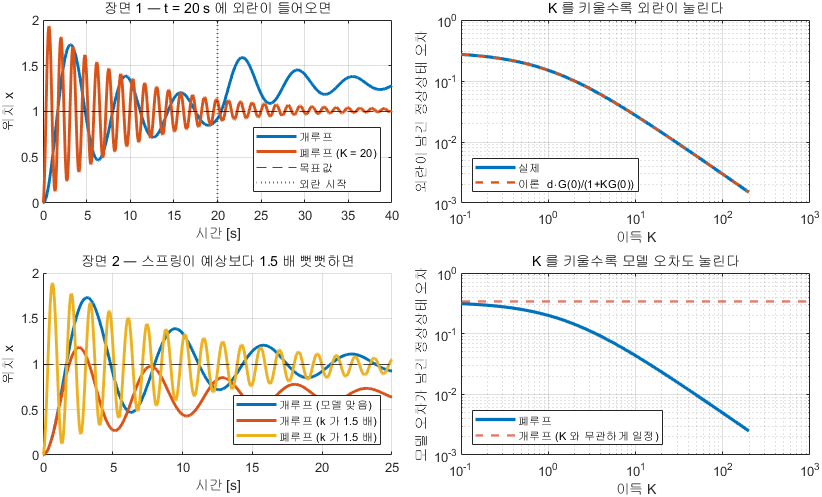

위 두 칸은 외란, 아래 두 칸은 모델 오차

**그림 파일** `w01_two_scenes.png` — `make_figures.m` 의 `fig_w01_two_scenes` · 다시 만들려면 `make_figures('w01_two_scenes')`

**만드는 곳** — `make_figures.m` 의 `fig_w01_two_scenes` **직접 바꿔 보려면** — `W01_01_open_vs_closed.m` (외란) 과 `W01_02_model_uncertainty.m` (모델 오차) 이 각각의 장면을 자세히 다룹니다

그림 해석 — **왼쪽 두 칸이 시간, 오른쪽 두 칸이 이득에 대한 그래프입니다**

마지막 줄이 핵심입니다. **전혀 달라 보이는 두 문제가 같은 답을 갖습니다.** 그 공통의 답이 다음 절의 감도함수 $1/(1+KG)$ 입니다.

왼쪽 두 칸은 **시간응답**, 오른쪽 두 칸은 **이득을 바꿔 가며 본 정상상태 오차**입니다.

왼쪽 위에서 읽을 것

- $t = 20$ s 에 외란이 들어오는 순간 개루프는 그대로 밀려나 **돌아오지 못한다**

- 폐루프는 잠깐 흔들렸다가 목표값으로 **되돌아온다**

왼쪽 아래에서 읽을 것

- 스프링이 예상보다 $1.5$ 배 뻣뻣하면 개루프는 그만큼 **덜 움직인 채로 끝난다**

- 폐루프는 거의 목표값에 닿는다

오른쪽 두 칸이 오늘의 핵심입니다. **두 그래프의 모양이 같습니다.** 원인이 외란이든 모델 오차든, $K$ 를 키우면 같은 비율로 줄어듭니다.

## 8-D. 감도를 이득별로 — 얼마나 줄어드는가

앞의 8-A · 8-B 에서 두 문제 모두 $S = \frac{1}{1+KG}$ 가 나오는 것을 보았습니다. 이제 그 값이 이득에 따라 어떻게 변하는지 봅니다.

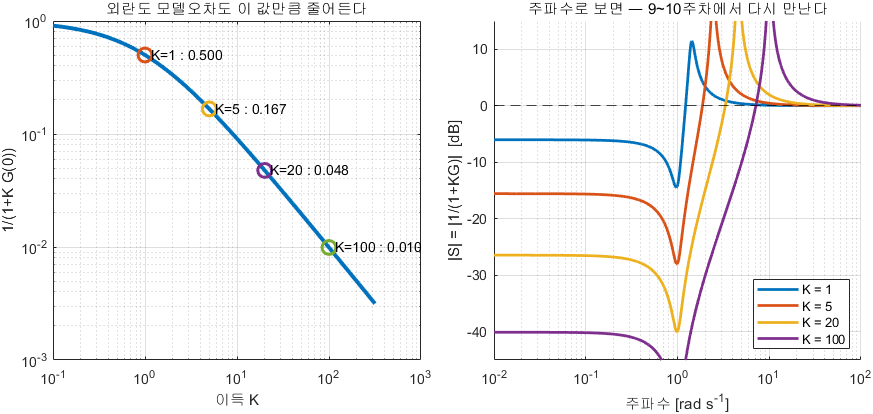

감도 하나가 두 효과를 모두 설명한다

**그림 파일** `w01_sensitivity.png` — `make_figures.m` 의 `fig_w01_sensitivity` · 다시 만들려면 `make_figures('w01_sensitivity')`

**만드는 곳** — `make_figures.m` 의 `fig_w01_sensitivity` **직접 확인해 보려면** — 명령창에 `1/(1+20*dcgain(plant_msd()))` 를 쳐 보면 왼쪽 그림의 $K=20$ 점이 나옵니다

그림 해석

**왼쪽만 보면 **$K$** 를 무한히 키우고 싶어집니다.** 오른쪽을 보십시오. 어떤 주파수에서는 외란을 **오히려 키웁니다.** 이 봉우리를 다루는 법이 10주차의 안정여유이고, 그때 이 그림을 다시 봅니다.

오른쪽 그림은 이 값을 주파수별로 그린 것입니다. 지금은 "저주파에서 작다" 정도만 보면 됩니다. **10주차에서 이 그림이 다시 나옵니다.**

fprintf('\n=== 감도 S = 1/(1+K*G(0)) 를 이득별로 ===\n');


=== 감도 S = 1/(1+K*G(0)) 를 이득별로 ===


fprintf('      K     루프이득 K*G(0)    S       외란·모델오차가 줄어드는 배수\n');

      K     루프이득 K*G(0)    S       외란·모델오차가 줄어드는 배수


fprintf('   ------  ---------------  -------  ------------------------------\n');

   ------  ---------------  -------  ------------------------------


for Kq = [1 5 20 50 100]
    Lq = Kq*dcgain(G_design);
    fprintf('   %6d  %15.1f  %7.4f  %26.1f 배\n', Kq, Lq, 1/(1+Lq), 1+Lq);
end

        1              1.0   0.5000                         2.0 배
        5              5.0   0.1667                         6.0 배
       20             20.0   0.0476                        21.0 배
       50             50.0   0.0196                        51.0 배
      100            100.0   0.0099                       101.0 배


fprintf('   --> K 를 5 배 키우면 오차도 대략 5 배 줄어듭니다.\n');

   --> K 를 5 배 키우면 오차도 대략 5 배 줄어듭니다.


fprintf('       다만 공짜가 아닙니다. 바로 다음 절에서 봅니다.\n\n');

       다만 공짜가 아닙니다. 바로 다음 절에서 봅니다.



## 8-E. 그러면 $K$ 를 무한히 키우면 되는가

좋은 질문이고, 답은 **안 된다**입니다.

- 4절에서 봤듯이 $K$ 를 키우면 진동이 심해진다

- 더 키우면 아예 불안정해진다

- 즉 $K$ 에는 **넘을 수 없는 상한**이 있다

그 상한을 계산하고 한계 안에서 최선을 뽑아내는 것이 앞으로 배울 내용입니다.

- **5주차** 안정도 — $K$ 를 얼마까지 키울 수 있는가

- **6~7주차** 근궤적 — $K$ 를 바꾸면 극점이 어디로 움직이는가

- **10주차** 안정여유 — 불안정까지 얼마나 여유가 있는가

## 3부 — Simulink 로 확인하기

- 지금까지는 전달함수로 **계산**했다

- 이제 블록선도로 **시뮬레이션**한다

왜 두 번 하는가

- 전달함수는 수학적 표현, 블록선도는 물리적 구성. 둘이 같다는 확신이 있어야 앞으로 마음 놓고 오갈 수 있다

- 실무에서 플랜트 모델은 대부분 전달함수가 아니라 **Simulink 블록선도**로 온다

- 포화나 잡음처럼 전달함수로 표현할 수 없는 요소가 들어오면 Simulink 만이 답을 준다. 6주차부터 바로 필요해진다

## 9-1. 모델 열어 보기

모델 구성

- 위쪽 — 개루프

- 아래쪽 — 폐루프

- 두 경로에 똑같은 외란이 들어간다

- **다른 점은 아래쪽에만 되먹임 선이 있다는 것뿐**

블록과 우리가 배운 것의 대응

- `Step` — 목표값 $r$. MATLAB 의 `step` 과 같은 역할

- `Gain` — $K_{ff}$, $K_r$, $K$. 신호에 상수를 곱함

- `Sum` — 더하기와 빼기. 부호가 `+-` 면 첫 입력에서 둘째를 뺌. 폐루프의 오차 계산이 바로 이 블록

- `Transfer Fcn` — 플랜트 $G$. 분자와 분모 계수를 적어 넣음

- `Mux` — **여러 신호를 한 줄로 묶는 블록**. 오늘 처음 나옵니다

- `Scope` — 결과를 그래프로 보여 주는 창

- `To Workspace` — 결과를 MATLAB 변수로 내보내기

`Mux` 를 왜 쓰는가

- Scope 블록은 입력 포트 하나에 신호 하나만 받는다

- 그런데 우리는 개루프 출력·폐루프 출력·목표값 **세 개를 한 화면에 겹쳐** 보고 싶다

- Scope 의 입력 포트를 세 개로 늘려도 되지만, 그러면 창 안에서 축이 세 칸으로 나뉜다

- `Mux` 로 먼저 묶어서 한 포트에 넣으면 **한 축 위에 세 곡선이 겹쳐** 그려진다. 비교가 목적일 때는 이쪽이 낫다

- MATLAB 으로 치면 `plot(t, [y1 y2 y3])` 처럼 열을 나란히 붙이는 것과 같다. 묶는 순서가 곧 범례의 순서가 된다

- 반대로 묶인 신호를 다시 갈라내는 블록은 `Demux` 다. 14주차에서 쓴다

## 9-2. Simulink 만으로 실행하기

**스크립트 없이 모델을 열고 실행해도 됩니다.**

- 모델을 열고 `Ctrl+T` 를 누르면 Scope 창 두 개가 자동으로 열린다

- 위쪽 Scope — 개루프 출력, 폐루프 출력, 목표값 세 신호

- 아래쪽 Scope — 폐루프의 제어입력 $u$

꼭 확인할 것

- $t=40\,\mathrm{s}$ 에 외란이 들어오면 **제어입력이 자동으로 커진다**

- 이것이 피드백이 일하는 모습이다

블록에 숫자가 아니라 변수 이름이 적혀 있는데도 실행되는 이유는, 모델을 열 때 기본값을 스스로 준비하도록 해 두었기 때문입니다.

## 9-3. 스크립트로 실행하고 결과 대조하기

`W01_03_run_simulink.m` 이 하는 일

- 파라미터를 워크스페이스에 설정

- `sim` 으로 모델 실행

- 같은 계산을 MATLAB 에서도 수행

- 두 결과의 최대 차이를 숫자로 출력

`sim` 사용법

- **입력** — `out = sim('모델이름')`. 모델이 필요로 하는 변수를 미리 만들어 둘 것

- **출력** — 결과 객체. 모델 안 `To Workspace` 블록에 적은 이름으로 꺼냄. 예를 들어 `out.y_open_sim`

- 꺼낸 결과는 `timeseries` 형식이라 시간은 `.Time`, 값은 `.Data` 로 접근

결과 읽기

- 최대 차이가 $10^{-4}\,\mathrm{m}$ 수준으로 나온다

- 완전히 $0$ 이 아닌 이유는 Simulink 가 수치적분을 하기 때문

- 이 정도면 같다고 본다

## 10. 오늘의 정리

- 모델이 정확하고 외란이 없으면 **개루프도 완벽**하다. 피드백이 항상 필요한 것은 아니다

- 피드백이 해 주는 일은 둘 — **외란을 밀어내는 것**, **모델이 틀려도 버티는 것**

- 두 효과의 크기는 모두 $S = \frac{1}{1+KG}$ 이며, 루프이득이 클수록 좋아진다

- 그런데 루프이득을 키우면 진동이 심해지고 결국 불안정해진다. **이 맞바꿈이 제어공학의 거의 전부다**

- 비례제어만으로는 감쇠를 만들 수 없다 → 미분제어 D (7주차)

- 정상상태 오차를 근본적으로 없애려면 오차를 누적해야 한다 → 적분제어 I (11주차)

- MATLAB 명령 아홉 개를 익혔다. 앞으로 계속 쓴다

## 11. 다음 주 예고

오늘 우리는 $G(s) = \frac{1}{ms^2+bs+k}$ 를 유도 없이 받아서 썼습니다. 2주차에서는 이 전달함수가 **어디서 오는지**를 다룹니다.

- 물리 법칙에서 미분방정식 세우기

- 라플라스 변환으로 전달함수 얻기

- 극점과 영점이 무엇이며 왜 그것만 알면 응답 모양을 짐작할 수 있는지

오늘 `pole` 과 `damp` 로 살짝 맛본 내용을 제대로 파고듭니다.